# Final Project - Walter and Yehya

## MidFoot Step

load midfootStep.mat
Acceleration;

midfoot_timeList = Acceleration.(Acceleration.Properties.DimensionNames{1});
midfoot_timeInSeconds = seconds(midfoot_timeList - midfoot_timeList(1));


midfootAccel =  timetable2table(Acceleration);
midfootAccel;

midfoot_final = table2array(midfootAccel(:,2:4));
midfoot_final;

midfoot_q = midfoot_timeInSeconds;

midfoot_finalArray = [midfoot_q midfoot_final];
midfoot_finalArray;


% this is unimportant ==>                       % midfoot_yaxis = plot(midfoot_finalArray(:,1), midfoot_finalArray(:,3));
                                                % midfoot_zaxis = plot(midfoot_finalArray(:,1), midfoot_finalArray(:,4));

% % midfoot_xaxis;
% plot(midfoot_finalArray(:,1), midfoot_finalArray(:,2));
% title("Uncropped X-Axis Acceleration vs Time");
% xlabel("Time (s)");
% ylabel("X-Axis Acceleration");
% % midfoot_yaxis;
% plot(midfoot_finalArray(:,1), midfoot_finalArray(:,3));
% title("Uncropped Y-Axis Acceleration vs Time");
% xlabel("Time (s)");
% ylabel("Y-Axis Acceleration");
% % midfoot_zaxis;
% plot(midfoot_finalArray(:,1), midfoot_finalArray(:,4));
% title("Uncropped Z-Axis Acceleration vs Time");
% xlabel("Time (s)");
%  ylabel("Z-Axis Acceleration");


% UNIMPORTANT - USED TO FIGURE OUT INDEX -->  plot(midfoot_finalArray(751:1376, 1), midfoot_finalArray(751:1376, 4)); % z acceleration vs time (CROPPED) NEED TO CHANGE THE SCALE (?)
% Crop data at t = 12-22
% V = valid data that we can use
Vmidfoot_time_data = midfoot_finalArray(751:1376, 1);
Vmidfoot_xaxis_data = midfoot_finalArray(751:1376, 2);
Vmidfoot_yaxis_data = midfoot_finalArray(751:1376, 3);
Vmidfoot_zaxis_data = midfoot_finalArray(751:1376, 4);

% new array for midfootStep data
midfootStep_FINAL = [Vmidfoot_time_data Vmidfoot_xaxis_data Vmidfoot_yaxis_data Vmidfoot_zaxis_data] % <==== THIS IS THE DATA ARRAY THAT WE ARE USING

midfootStep_FINAL =    12.0000    1.5047   -1.6786   -0.3823
   12.0160   -1.3129   -2.8066    2.0579
   12.0320   -4.5060   -3.8707    3.8367
   12.0480   -7.0393   -3.1541    1.3796
   12.0640   -7.7987   -0.2385   -5.3030
   12.0800    0.9597    0.3997  -11.1294
   12.0960   11.0938   -3.3094    0.1539
   12.1120   15.5552  -22.6915    9.8870
   12.1280  -10.2103  -35.1450   13.2617
   12.1440   -8.1300  -19.4681    5.0187


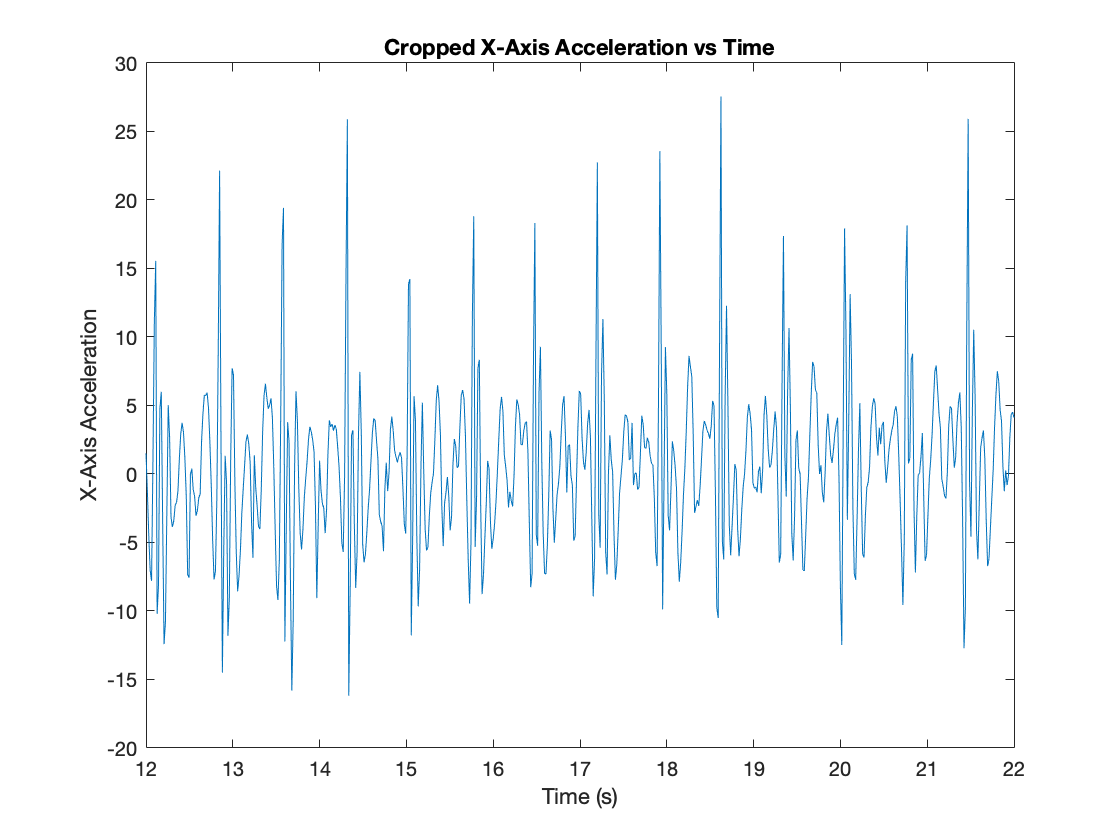


%---- New Cropped Data - PLOTS -----
        
%Cropped data for x-axis acceleration vs time
plot(midfootStep_FINAL(:,1), midfootStep_FINAL(:,2));
title("Cropped X-Axis Acceleration vs Time");
xlabel("Time (s)");
ylabel("X-Axis Acceleration");

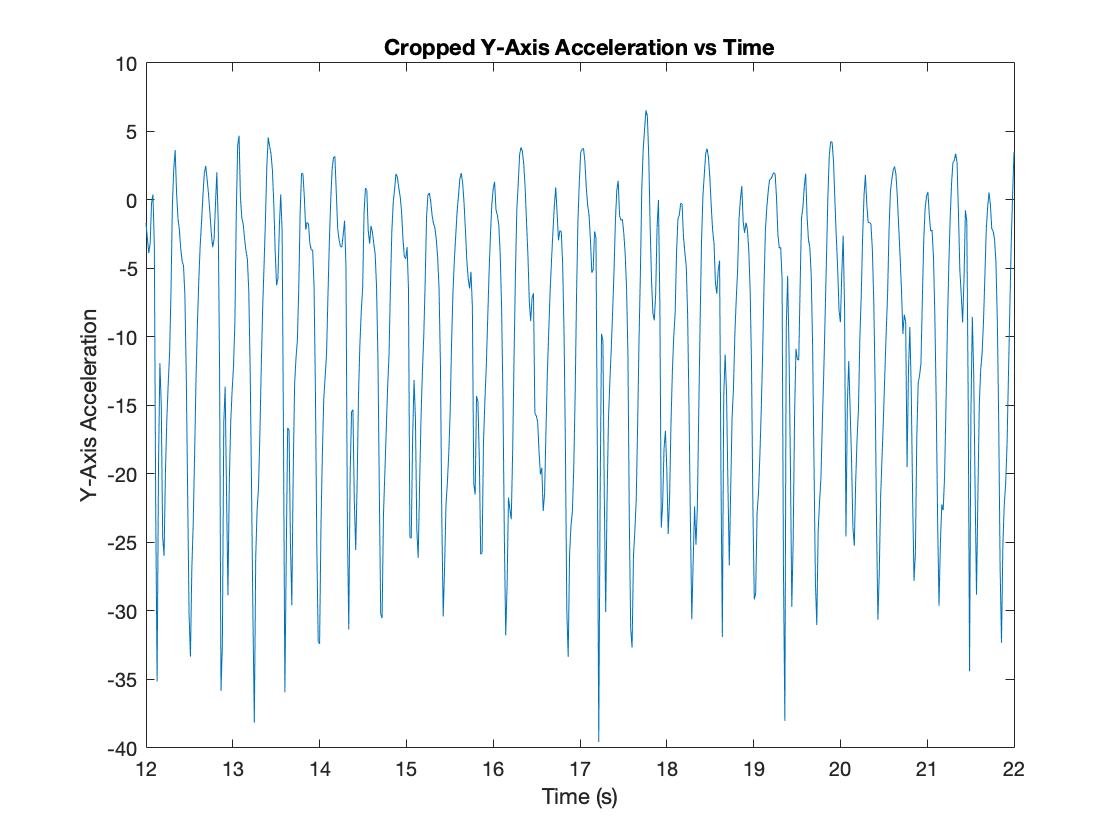



%Cropped data for y-axis acceleration vs time
plot(midfootStep_FINAL(:,1), midfootStep_FINAL(:,3));
title("Cropped Y-Axis Acceleration vs Time");
xlabel("Time (s)");
ylabel("Y-Axis Acceleration");

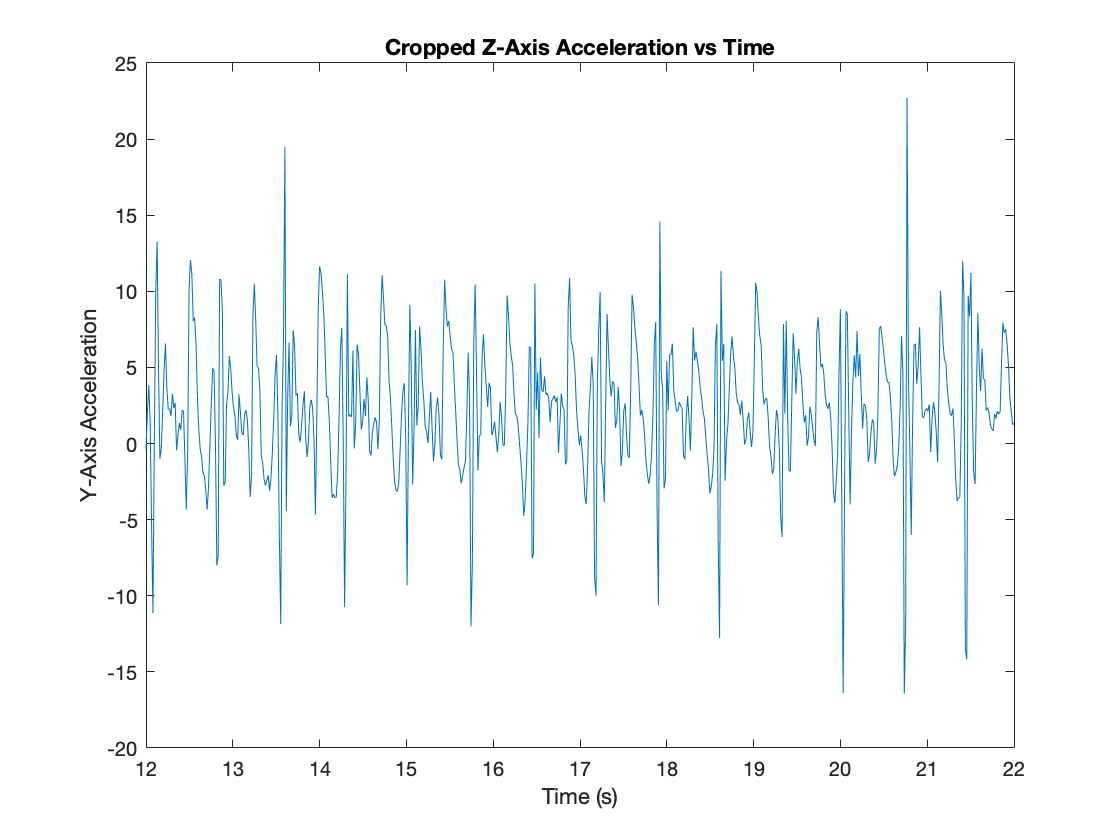


%Cropped data for z-axis acceleration vs time
plot(midfootStep_FINAL(:,1), midfootStep_FINAL(:,4));
title("Cropped Z-Axis Acceleration vs Time");
xlabel("Time (s)");
 ylabel("Y-Axis Acceleration");

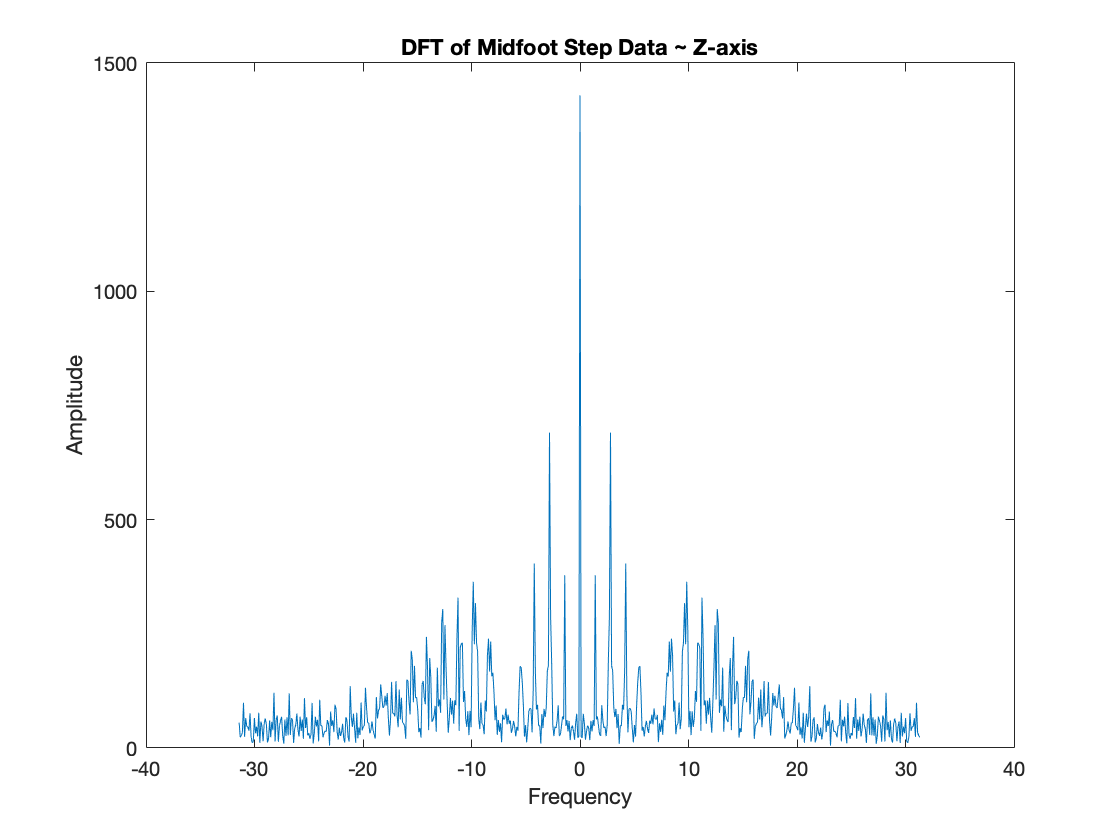



% Plotting the DFT for Z-Axis Acceleration %
P_mid = fftshift(fft(midfootStep_FINAL(:,4)));
Fs = 10; %sampling frequency (Hz)
N_mid = length(P_mid);
F_mid = (linspace(-pi, pi-2/N_mid*pi, N_mid) + pi/N_mid*mod(N_mid,2))* Fs; %Domain in Hertz%
 %convert from rad to Hz

plot(F_mid,abs(P_mid')) % Plotting the DFT
title("DFT of Midfoot Step Data ~ Z-axis");
xlabel("Frequency");
ylabel("Amplitude")


 
 % y = fft(midfootStep_FINAL);

% t = Vmidfoot_time_data';
% dt = mean(diff(t));
% F = 10 / dt;
% f = (0:length(y)-1)*50/length(y);   % Q: how do we find sampling frequency 
% plot(F, abs(y))



## Heel Step

load heelStep.mat

Acceleration;

heelstep_timeList = Acceleration.(Acceleration.Properties.DimensionNames{1});
heelstep_timeInSeconds = seconds(heelstep_timeList - heelstep_timeList(1));

heelStepAccel = timetable2table(Acceleration);
heelStepAccel;

heelstep_final = table2array(heelStepAccel(:, 2:4));
heelstep_final;

heelstep_q = heelstep_timeInSeconds;

heelstep_finalArray = [heelstep_q heelstep_final];
heelstep_finalArray

heelstep_finalArray =          0   -0.3900    2.2163    9.7391
    0.0160   -0.1180    2.1718    9.8291
    0.0320   -0.0384    2.0501   10.2797
    0.0480    0.0860    2.0236   10.5503
    0.0640    0.2789    2.3207    9.6022
    0.0800   -0.0695    2.4966    8.4416
    0.0960   -0.5797    2.3813    8.4105
    0.1120   -0.8766    2.0216    8.9539
    0.1280   -0.2220    1.8802    9.8468
    0.1440    0.9179    2.4266    9.4509





% NEW DATA %
% Crop data at t = 10-20
% V = valid data that we can use
Vheelstep_time_data = heelstep_finalArray(626:1251, 1);
Vheelstep_xaxis_data = heelstep_finalArray(626:1251, 2);
Vheelstep_yaxis_data = heelstep_finalArray(626:1251, 3);
Vheelstep_zaxis_data = heelstep_finalArray(626:1251, 4);

% NEW ARRAY for heelStep data
heelStep_FINAL = [Vheelstep_time_data Vheelstep_xaxis_data Vheelstep_yaxis_data Vheelstep_zaxis_data] % <==== THIS IS THE DATA ARRAY THAT WE ARE USING

heelStep_FINAL =    10.0000   -1.8185  -11.7256    1.4410
   10.0160   -0.3651  -10.2315    1.2614
   10.0320    1.0388   -8.7221    3.0890
   10.0480    1.1538   -7.2259    4.8038
   10.0640    1.0629   -5.2698    4.6952
   10.0800    1.4946   -2.3623    1.3186
   10.0960    1.4986    1.2276   -2.5880
   10.1120    0.2509    1.7212    0.6670
   10.1280    1.3504   -3.7146    3.9307
   10.1440    3.6500   -9.7989    4.0408


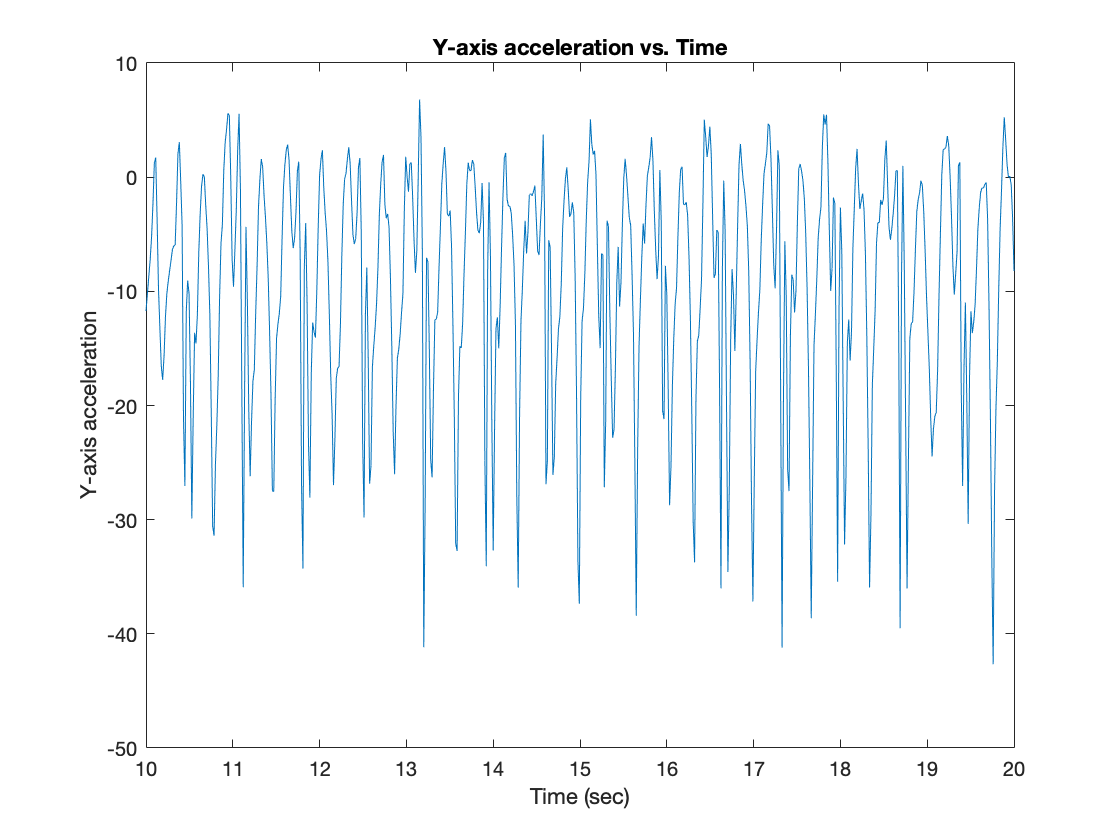


plot(heelStep_FINAL(:,1), heelStep_FINAL(:,3));
title("Y-axis acceleration vs. Time");
xlabel("Time (sec)");
ylabel("Y-axis acceleration")

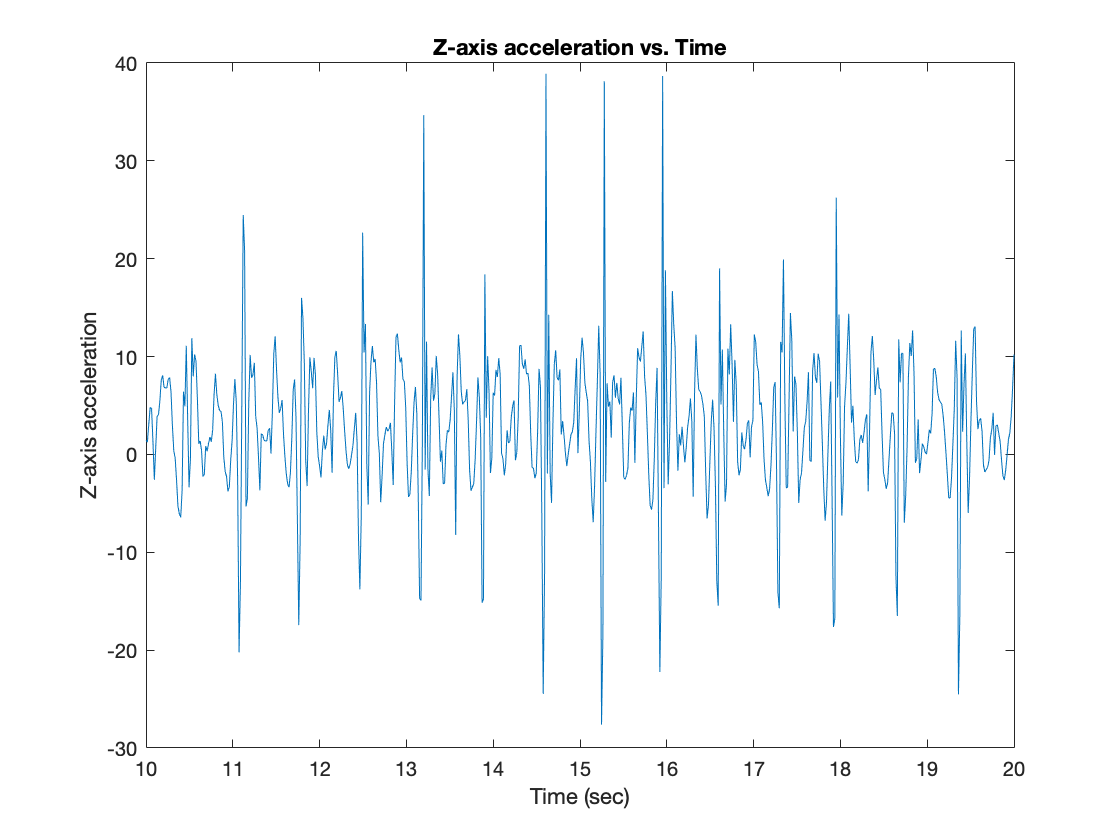


plot(heelStep_FINAL(:,1), heelStep_FINAL(:,4));
title("Z-axis acceleration vs. Time");
xlabel("Time (sec)");
ylabel("Z-axis acceleration")

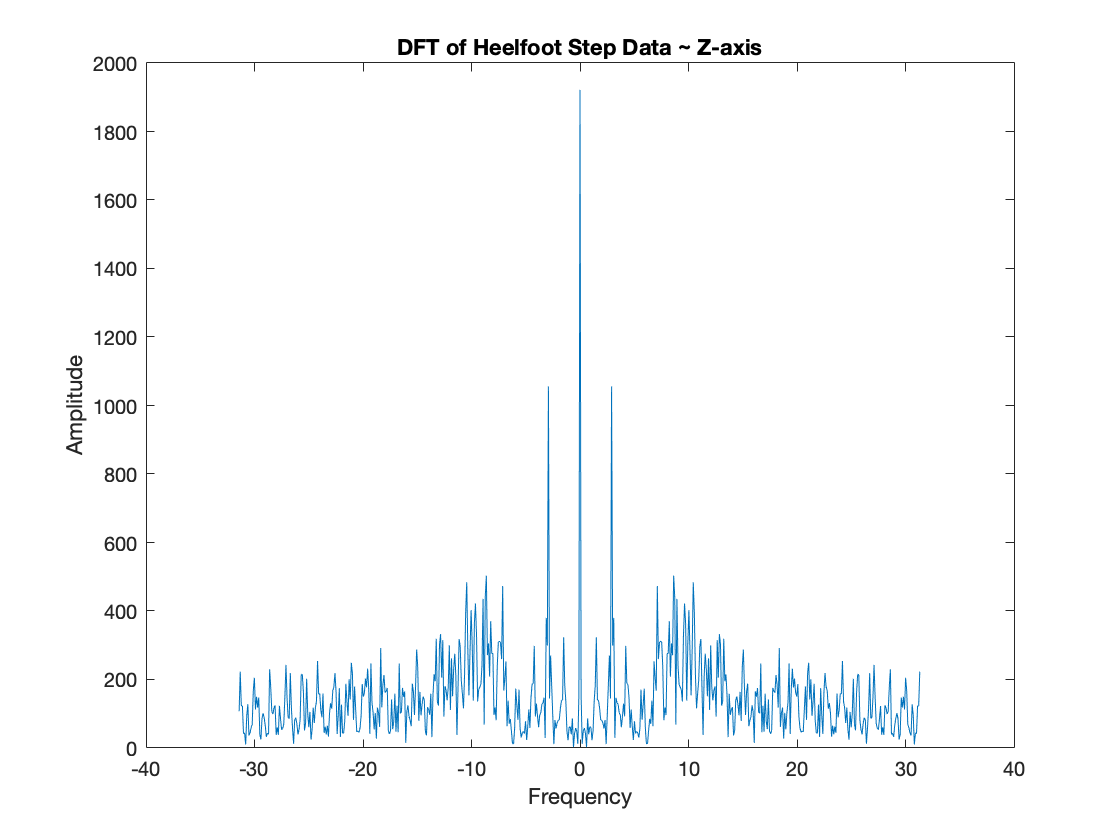



% Plotting the DFT for Z-Axis Acceleration %


P_heel = fftshift(fft(heelStep_FINAL(:,4)));
Fs = 10; %sampling frequency (Hz)
N_heel = length(P_heel);
F_heel = (linspace(-pi, pi-2/N_heel*pi, N_heel) + pi/N_heel*mod(N_heel,2)) * Fs; %Domain in Hertz%


plot(F_heel,abs(P_heel')) % Plotting the DFT
title("DFT of Heelfoot Step Data ~ Z-axis");`
xlabel("Frequency");
ylabel("Amplitude")

## Toe Step

load toeStep.mat
Acceleration;

toestep_timeList = Acceleration.(Acceleration.Properties.DimensionNames{1});
toestep_timeInSeconds = seconds(toestep_timeList - toestep_timeList(1));

toeStepAccel = timetable2table(Acceleration);
toeStepAccel;

toestep_final = table2array(toeStepAccel(:, 2:4));
toestep_final;

toestep_q = toestep_timeInSeconds

toestep_q =          0
    0.0160
    0.0320
    0.0480
    0.0640
    0.0800
    0.0960
    0.1120
    0.1280
    0.1440



toestep_finalArray = [toestep_q toestep_final];
toestep_finalArray

toestep_finalArray =          0   -2.3328    2.0645    9.4037
    0.0160   -2.5279    2.3136    8.9543
    0.0320   -2.6623    2.3604    8.9215
    0.0480   -2.7540    2.4238    9.0264
    0.0640   -2.8409    2.6367    9.3673
    0.0800   -2.9999    2.6307    8.9722
    0.0960   -2.7058    2.6298    8.7604
    0.1120   -2.7214    2.9822    8.3029
    0.1280   -2.9990    3.1645    8.2710
    0.1440   -3.6540    3.3955    7.8829



% NEW DATA %
% Crop data at t = 10-20
% % V = valid data that we can use
Vtoestep_time_data = toestep_finalArray(626:1251, 1);
Vtoestep_xaxis_data = toestep_finalArray(626:1251, 2);
Vtoestep_yaxis_data = toestep_finalArray(626:1251, 3);
Vtoestep_zaxis_data = toestep_finalArray(626:1251, 4);

% NEW ARRAY for heelStep data
toeStep_FINAL = [Vtoestep_time_data Vtoestep_xaxis_data Vtoestep_yaxis_data Vtoestep_zaxis_data] % <==== THIS IS THE DATA ARRAY THAT WE ARE USING

toeStep_FINAL =    10.0000   -2.4713   -4.3866    3.4829
   10.0160   -7.7556   -5.1413    5.6009
   10.0320   -9.9800   -6.2979   -5.1638
   10.0480    1.7804   -4.8485  -12.0486
   10.0640   11.5781  -10.9889   -4.7137
   10.0800   10.7653  -19.3509    2.6432
   10.0960   -4.6251  -30.6147    8.3119
   10.1120   -5.4087  -32.4970   17.9542
   10.1280   -3.9380  -18.0406   10.4010
   10.1440   -6.7773  -15.6672   -2.7911


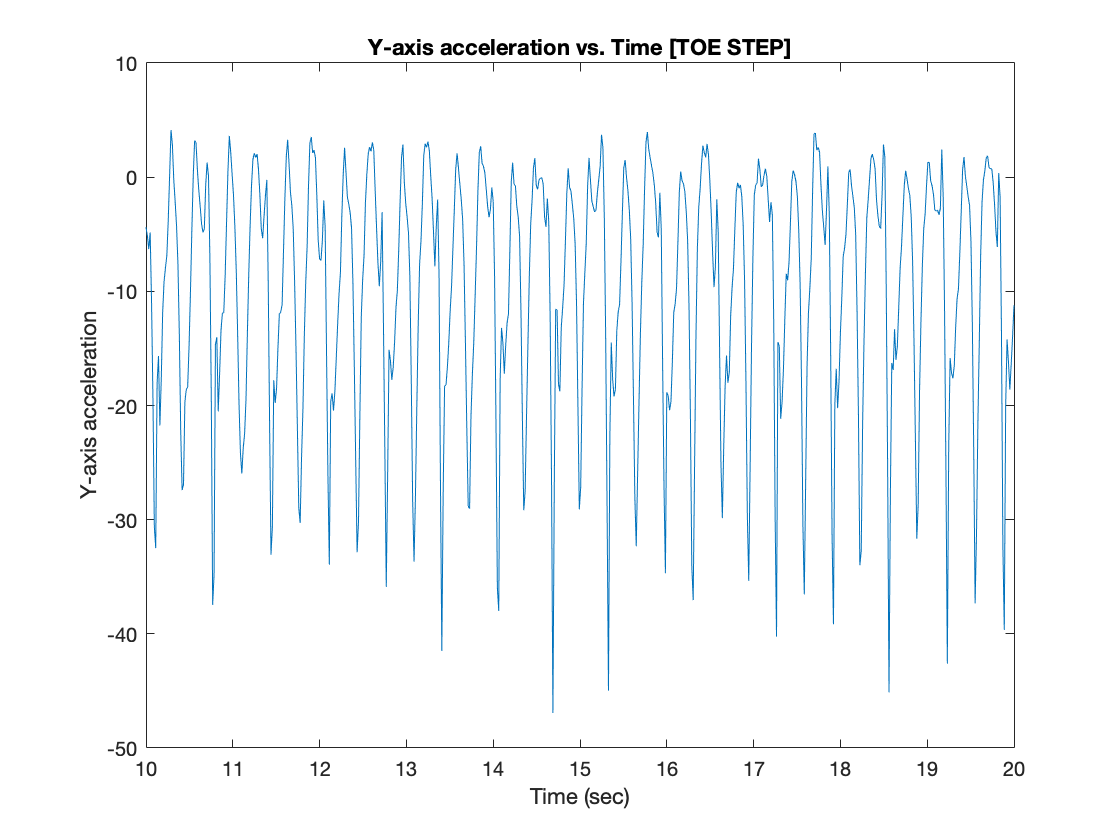


% plot(toestep_finalArray(:,1), toestep_finalArray(:,4));

plot(toeStep_FINAL(:,1), toeStep_FINAL(:,3));
title("Y-axis acceleration vs. Time [TOE STEP]");
xlabel("Time (sec)");
ylabel("Y-axis acceleration")

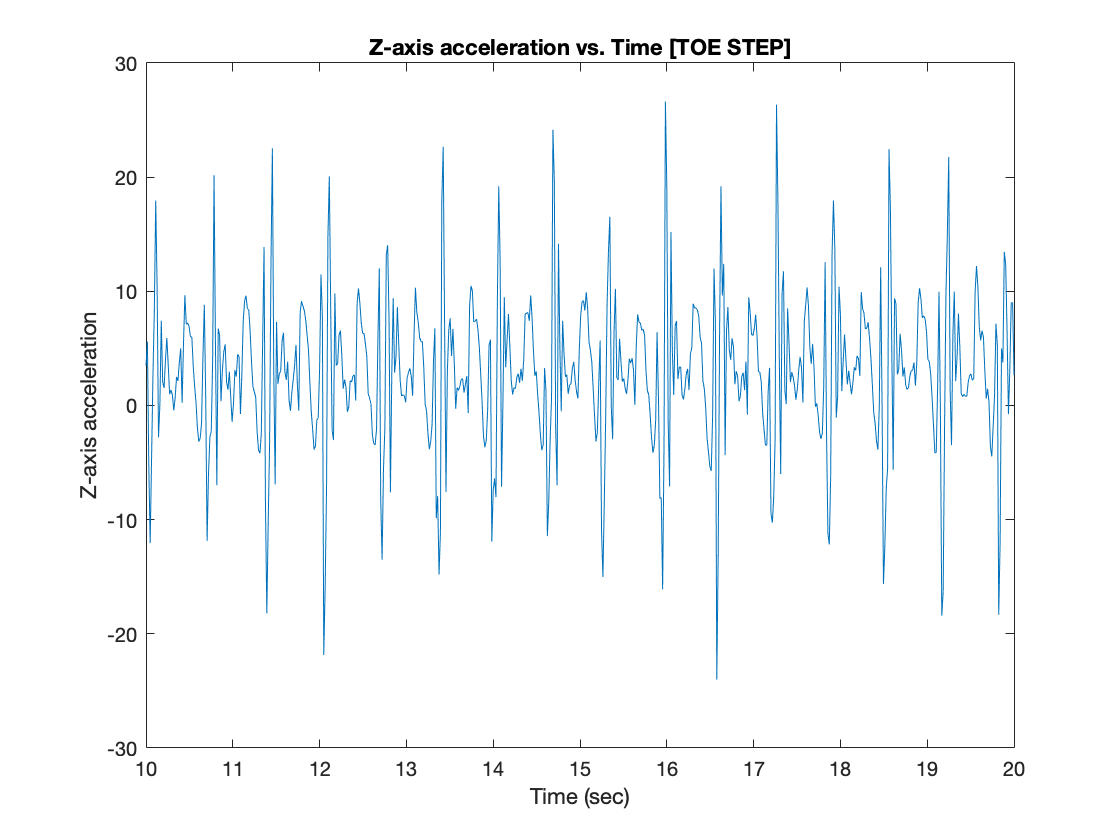


plot(toeStep_FINAL(:,1), toeStep_FINAL(:,4));
title("Z-axis acceleration vs. Time [TOE STEP]");
xlabel("Time (sec)");
ylabel("Z-axis acceleration")

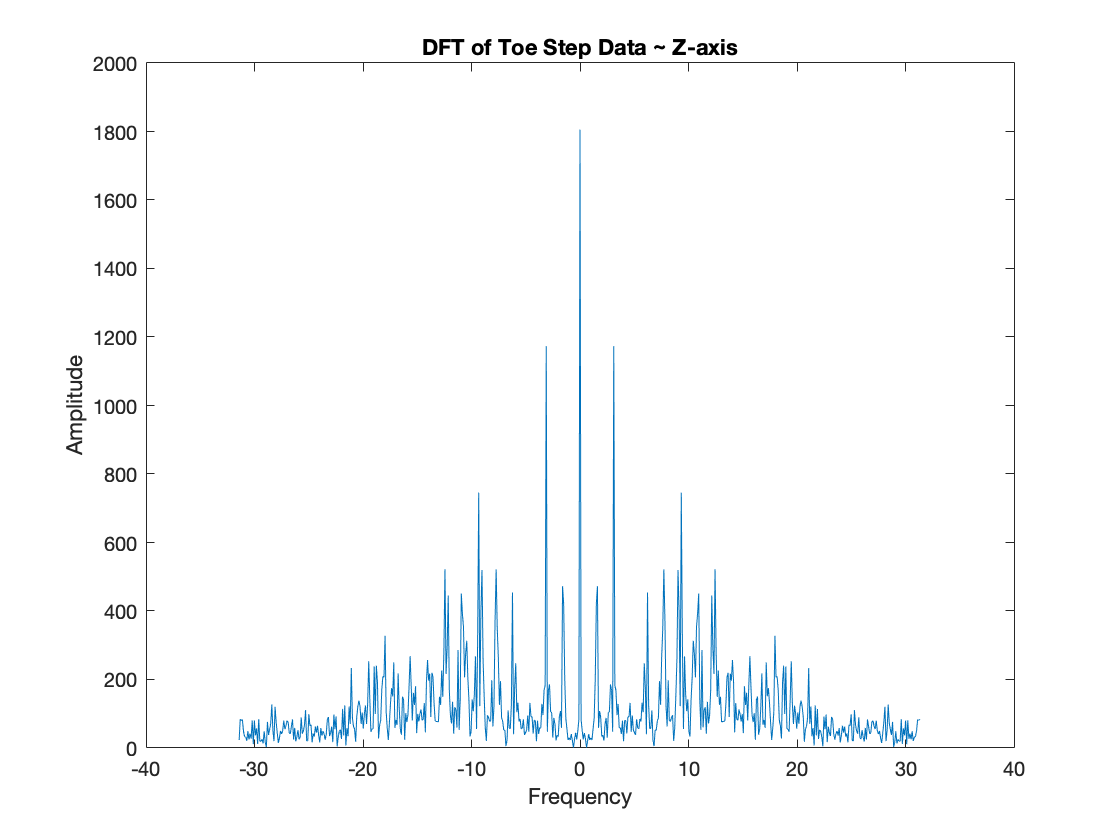



% Plotting the DFT for Z-Axis Acceleration %


P_toe = fftshift(fft(toeStep_FINAL(:,4)));
Fs = 10; %sampling frequency (Hz)
N_toe = length(P_toe);
F_toe = (linspace(-pi, pi-2/N_toe*pi, N_toe) + pi/N_toe*mod(N_toe,2)) * Fs; %Domain in Hertz%


plot(F_toe,abs(P_toe')) % Plotting the DFT
title("DFT of Toe Step Data ~ Z-axis");
xlabel("Frequency");
ylabel("Amplitude")

## New Data For More Trials - Walter's Data

load midstrike_walter.mat
Acceleration

Acceleration = 2724×3 timetable
           Timestamp               X           Y         Z   
    ________________________    ________    _______    ______

    13-Dec-2020 17:32:02.697     -2.0341     2.8558    8.0923
    13-Dec-2020 17:32:02.713      -2.392     2.4739    8.0597
    13-Dec-2020 17:32:02.730     -2.2453      2.592    8.3896
    13-Dec-2020 17:32:02.746     -1.7169     2.6139    8.5662
    13-Dec-2020 17:32:02.762     -1.1674     1.7918    8.6962
    13-Dec-2020 17:32:02.778     -1.3298      1.509    9.2072
    13-Dec-2020 17:32:02.794     -1.7349     1.1111    9.5082
    13-Dec-2020 17:32:02.811     -1.6497    0.46044    9.9564
    13-Dec-2020 17:32:02.827     -1.0625     1.5135    9.9



midstrikeW_timeList = Acceleration.(Acceleration.Properties.DimensionNames{1});
midstrikeW_timeInSeconds = seconds(midstrikeW_timeList - midstrikeW_timeList(1));

midstrikeW_Accel = timetable2table(Acceleration);
midstrikeW_Accel;

midstrikeW_final = table2array(midstrikeW_Accel(:,2:4));
midstrikeW_final;

midstrikeW_q = midstrikeW_timeInSeconds;

midstrikeW_finalArray = [midstrikeW_q midstrikeW_final];
midstrikeW_finalArray

midstrikeW_finalArray =          0   -2.0341    2.8558    8.0923
    0.0160   -2.3920    2.4739    8.0597
    0.0330   -2.2453    2.5920    8.3896
    0.0490   -1.7169    2.6139    8.5662
    0.0650   -1.1674    1.7918    8.6962
    0.0810   -1.3298    1.5090    9.2072
    0.0970   -1.7349    1.1111    9.5082
    0.1140   -1.6497    0.4604    9.9564
    0.1300   -1.0625    1.5135    9.9944
    0.1460   -0.2828    1.9626    9.0065


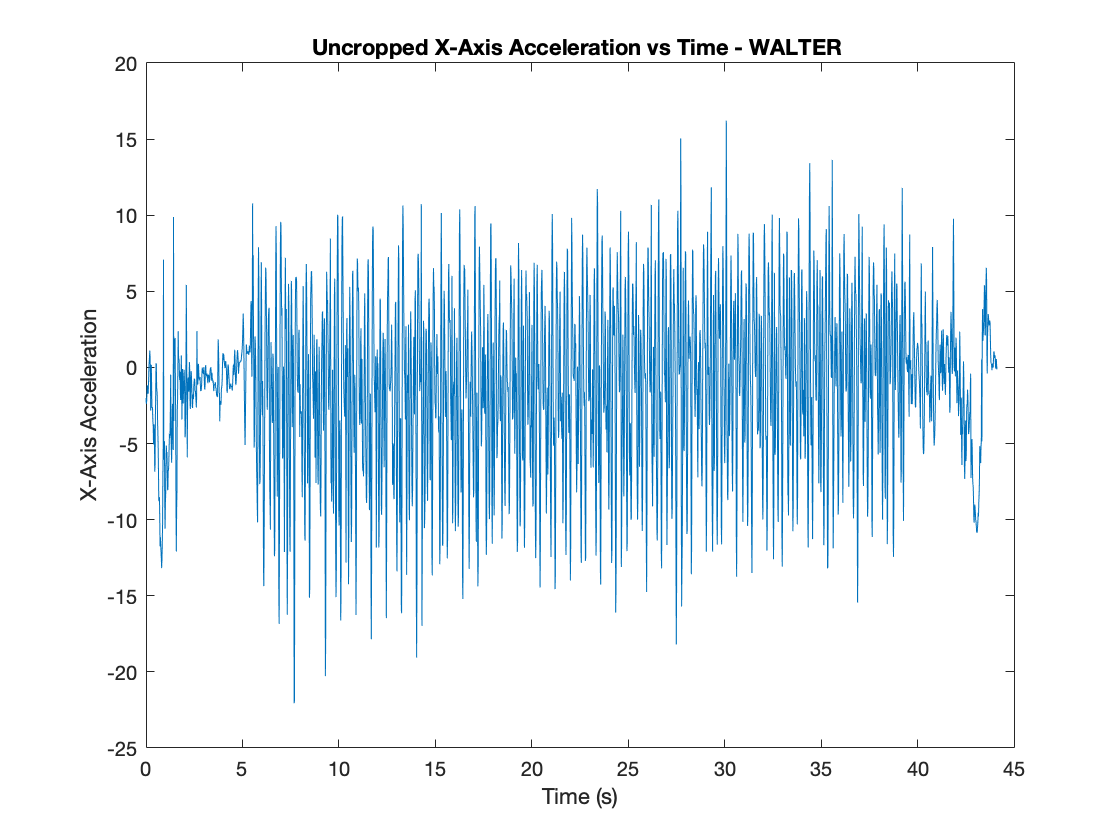


% midstrikeW_xaxis;
plot(midstrikeW_finalArray(:,1), midstrikeW_finalArray(:,2));
title("Uncropped X-Axis Acceleration vs Time - WALTER ");
xlabel("Time (s)");
ylabel("X-Axis Acceleration");

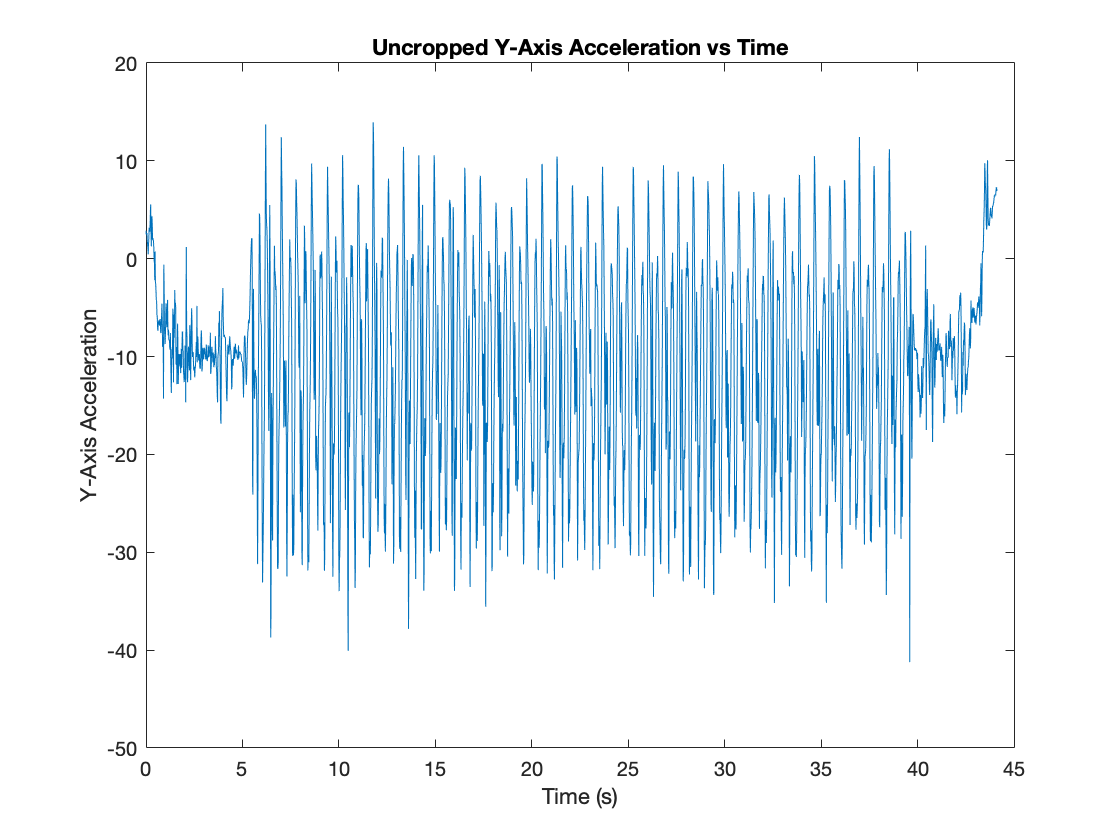


% midstrikeW_yaxis;
plot(midstrikeW_finalArray(:,1), midstrikeW_finalArray(:,3));
title("Uncropped Y-Axis Acceleration vs Time");
xlabel("Time (s)");
ylabel("Y-Axis Acceleration");

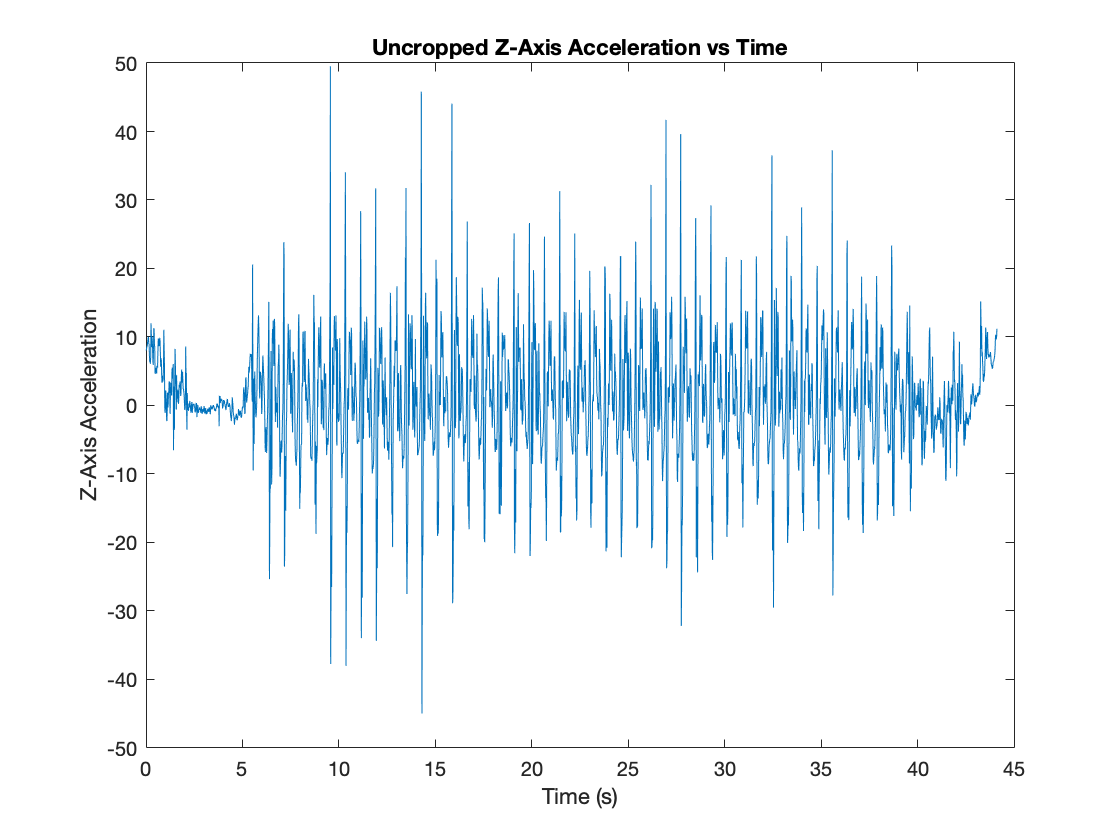


% midstrikeW_zaxis;
plot(midstrikeW_finalArray(:,1), midstrikeW_finalArray(:,4));
title("Uncropped Z-Axis Acceleration vs Time");
xlabel("Time (s)");
ylabel("Z-Axis Acceleration");


 
% UNIMPORTANT - USED TO FIGURE OUT INDEX  -->  plot(midfoot_finalArray(751:1376, 1), midfoot_finalArray(751:1376, 4)); % z acceleration vs time (CROPPED) NEED TO CHANGE THE SCALE (?)
% Crop data at t = 10.0130 - 40
% V = valid data that we can use
VmidstrikeW_time_data = midstrikeW_finalArray(619:2470, 1);
VmidstrikeW_xaxis_data = midstrikeW_finalArray(619:2470, 2);
VmidstrikeW_yaxis_data = midstrikeW_finalArray(619:2470, 3);
VmidstrikeW_zaxis_data = midstrikeW_finalArray(619:2470, 4);

% new array for midfootStep data
midstrikeW_FINAL = [VmidstrikeW_time_data VmidstrikeW_xaxis_data VmidstrikeW_yaxis_data VmidstrikeW_zaxis_data] % <==== THIS IS THE DATA ARRAY THAT WE ARE USING

midstrikeW_FINAL =    10.0130  -10.3868  -33.9729   -2.2040
   10.0290   -6.5252  -30.6754    2.1088
   10.0450   -3.4858  -30.3816    9.8434
   10.0610   -4.4574  -27.5096    5.8253
   10.0770  -10.6818  -20.5324    3.4602
   10.0940  -16.6258  -15.3250    1.9858
   10.1100  -15.2048  -11.8208   -2.3223
   10.1260   -7.0282   -9.5759   -5.7373
   10.1420    2.2058   -7.0602   -9.6849
   10.1580    8.0158   -1.9521  -10.6048


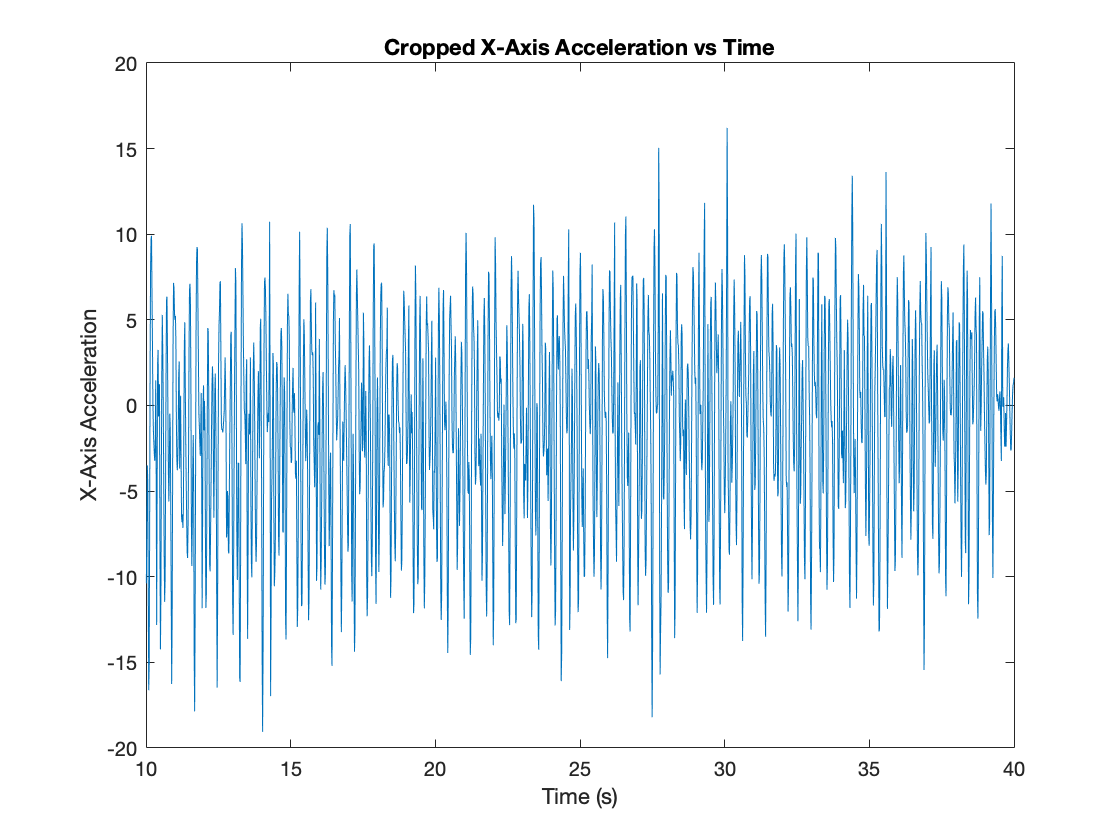


%---- New Cropped WALTER Data - PLOTS -----
        
%Cropped data for x-axis acceleration vs time
plot(midstrikeW_FINAL(:,1), midstrikeW_FINAL(:,2));
title("Cropped X-Axis Acceleration vs Time");
xlabel("Time (s)");
ylabel("X-Axis Acceleration");

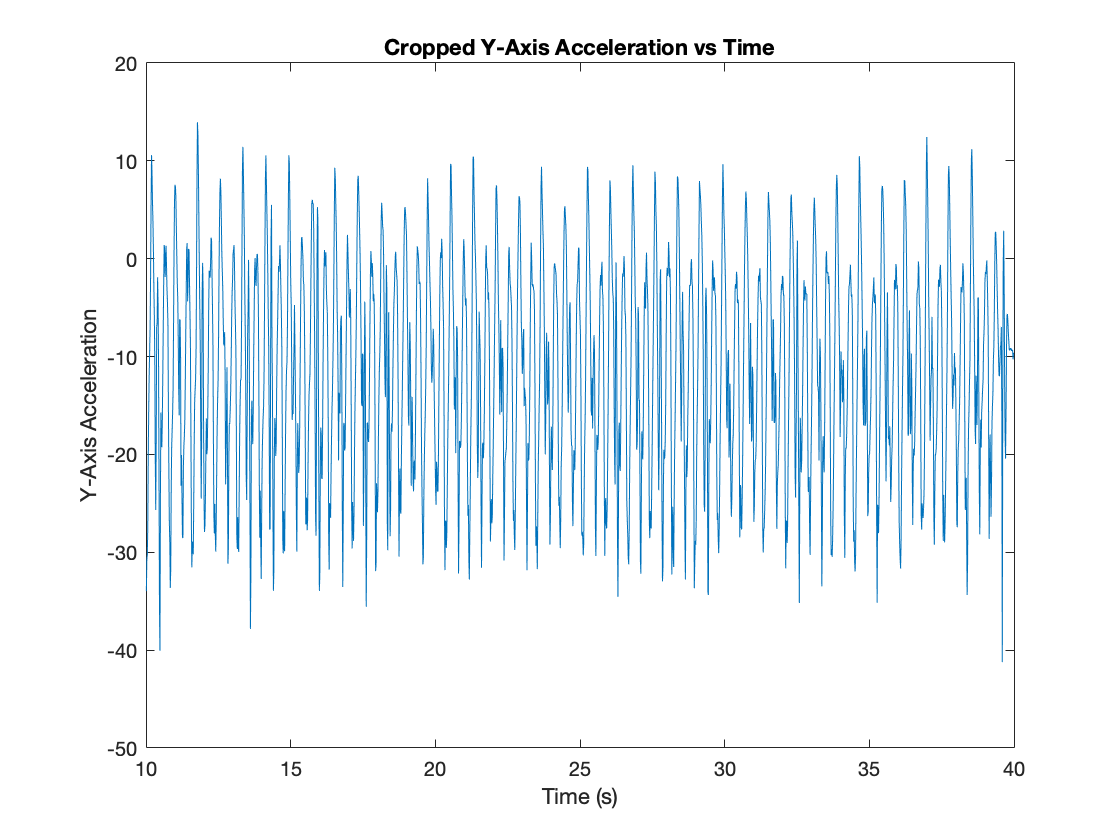



%Cropped data for y-axis acceleration vs time
plot(midstrikeW_FINAL(:,1), midstrikeW_FINAL(:,3));
title("Cropped Y-Axis Acceleration vs Time");
xlabel("Time (s)");
ylabel("Y-Axis Acceleration");

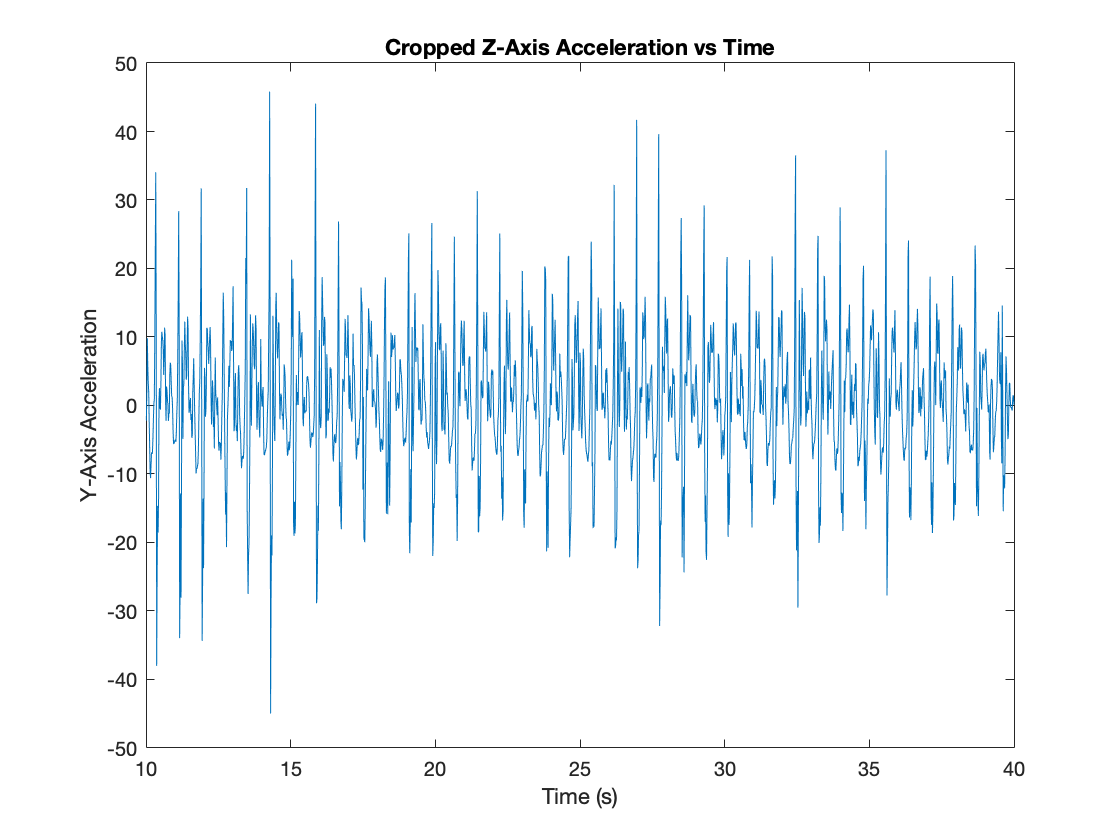


%Cropped data for z-axis acceleration vs time
plot(midstrikeW_FINAL(:,1), midstrikeW_FINAL(:,4));
title("Cropped Z-Axis Acceleration vs Time");
xlabel("Time (s)");
ylabel("Y-Axis Acceleration");

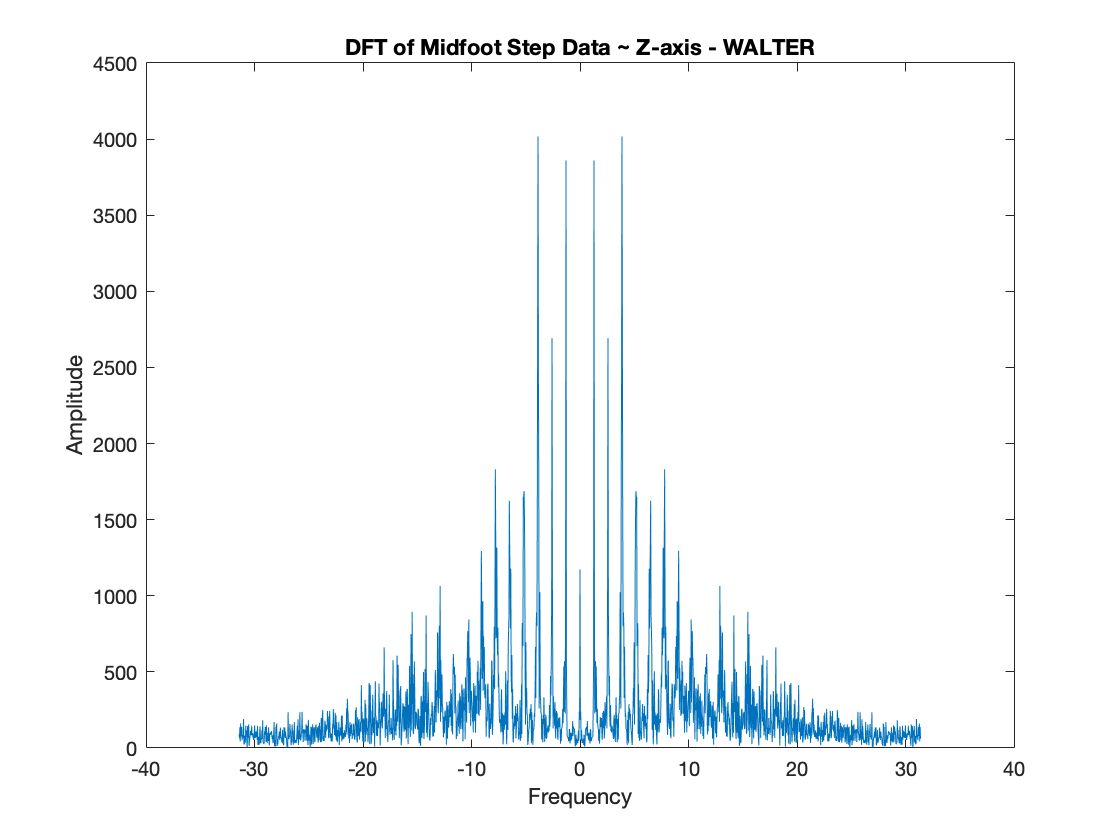



% Plotting the DFT for Z-Axis Acceleration %
P_midstrikeW = fftshift(fft(midstrikeW_FINAL(:,4)));
Fs = 10; %sampling frequency (Hz)
N_midstrikeW = length(P_midstrikeW);
F_midstrikeW = (linspace(-pi, pi-2/N_midstrikeW*pi, N_midstrikeW) + pi/N_midstrikeW*mod(N_midstrikeW,2))* Fs; %Domain in Hertz%


plot(F_midstrikeW,abs(P_midstrikeW')) % Plotting the DFT
title("DFT of Midfoot Step Data ~ Z-axis - WALTER");
xlabel("Frequency");
ylabel("Amplitude");

## Heelstrike for Walter

load heelstrike_walter.mat
Acceleration;

Acceleration = 2508×3 timetable
           Timestamp               X          Y         Z   
    ________________________    ________    ______    ______

    13-Dec-2020 17:27:58.951    -0.94663    2.3387    8.9801
    13-Dec-2020 17:27:58.967     -1.0028    2.4077    8.6685
    13-Dec-2020 17:27:58.984    -0.40386    2.8408    8.6617
    13-Dec-2020 17:27:59.000    -0.28725    2.2137    8.5161
    13-Dec-2020 17:27:59.016    -0.38066     2.194    9.1077
    13-Dec-2020 17:27:59.032    -0.41135    2.4988    9.3311
    13-Dec-2020 17:27:59.048    -0.49756    2.4287    9.3259
    13-Dec-2020 17:27:59.065    -0.18127    1.9702    8.7405
    13-Dec-2020 17:27:59.081    -0.12709     1.791    8.3216
    



heelstrikeW_timeList = Acceleration.(Acceleration.Properties.DimensionNames{1});
heelstrikeW_timeInSeconds = seconds(heelstrikeW_timeList - heelstrikeW_timeList(1));

heelstrikeW_Accel = timetable2table(Acceleration);
heelstrikeW_Accel;

heelstrikeW_final = table2array(heelstrikeW_Accel(:,2:4));
heelstrikeW_final;

heelstrikeW_q = heelstrikeW_timeInSeconds;

heelstrikeW_finalArray = [heelstrikeW_q heelstrikeW_final];
heelstrikeW_finalArray % <- Array that puts everything in a MATRIX

heelstrikeW_finalArray =          0   -0.9466    2.3387    8.9801
    0.0160   -1.0028    2.4077    8.6685
    0.0330   -0.4039    2.8408    8.6617
    0.0490   -0.2873    2.2137    8.5161
    0.0650   -0.3807    2.1940    9.1077
    0.0810   -0.4113    2.4988    9.3311
    0.0970   -0.4976    2.4287    9.3259
    0.1140   -0.1813    1.9702    8.7405
    0.1300   -0.1271    1.7910    8.3216
    0.1460   -0.6188    1.9584    7.7905


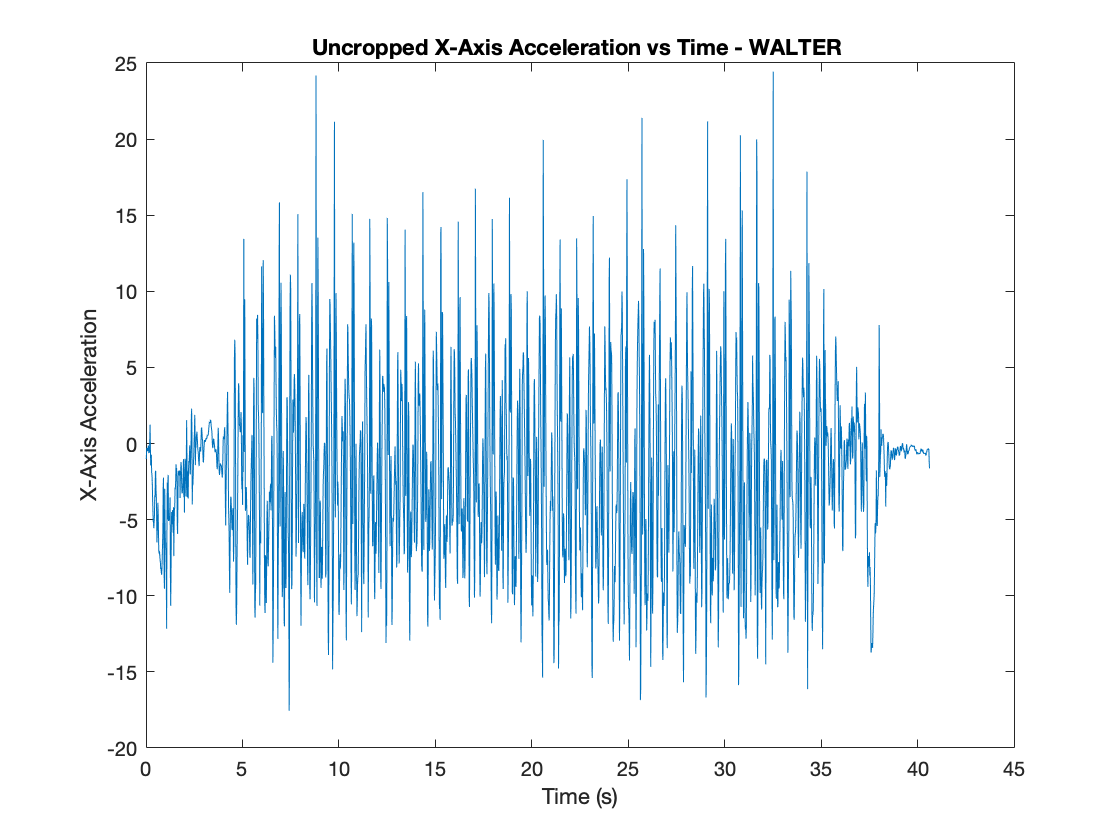


% heelstrikeW_xaxis;
plot(heelstrikeW_finalArray(:,1), heelstrikeW_finalArray(:,2));
title("Uncropped X-Axis Acceleration vs Time - WALTER ");
xlabel("Time (s)");
ylabel("X-Axis Acceleration");

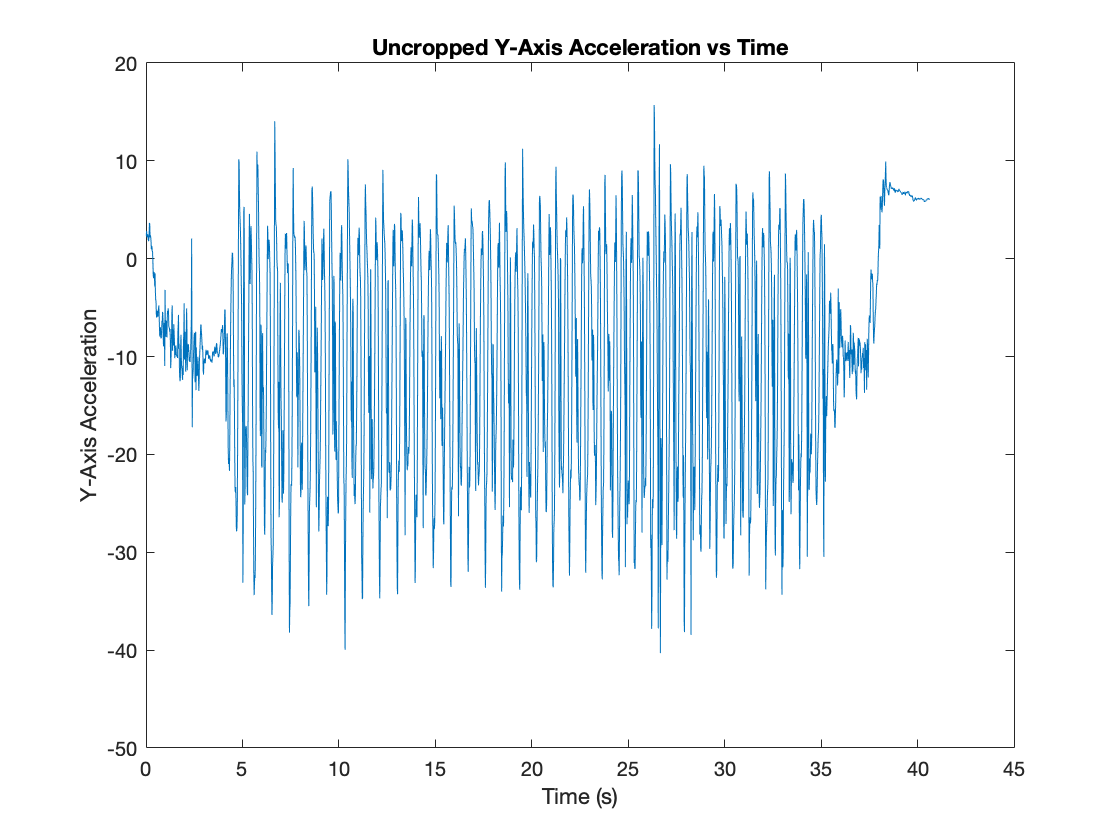


% heelstrikeW_yaxis;
plot(heelstrikeW_finalArray(:,1), heelstrikeW_finalArray(:,3));
title("Uncropped Y-Axis Acceleration vs Time");
xlabel("Time (s)");
ylabel("Y-Axis Acceleration");

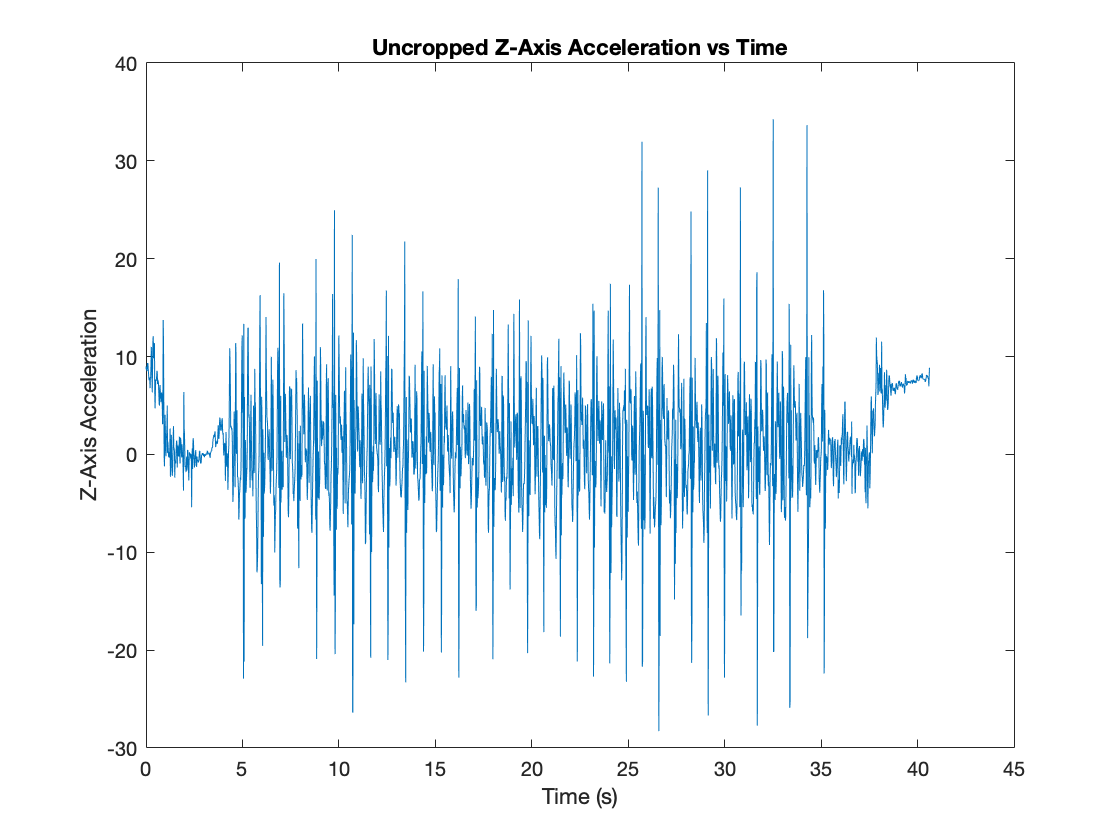


% heelstrikeW_zaxis;
plot(heelstrikeW_finalArray(:,1), heelstrikeW_finalArray(:,4));
title("Uncropped Z-Axis Acceleration vs Time");
xlabel("Time (s)");
ylabel("Z-Axis Acceleration");


 
% UNIMPORTANT - USED TO FIGURE OUT INDEX  -->  plot(midfoot_finalArray(751:1376, 1), midfoot_finalArray(751:1376, 4)); % z acceleration vs time (CROPPED) NEED TO CHANGE THE SCALE (?)
% Crop data at t = 5.0070 - 35.0120
% V = valid data that we can use
VheelstrikeW_time_data = heelstrikeW_finalArray(310:2162, 1);
VheelstrikeW_xaxis_data = heelstrikeW_finalArray(310:2162, 2);
VheelstrikeW_yaxis_data = heelstrikeW_finalArray(310:2162, 3);
VheelstrikeW_zaxis_data = heelstrikeW_finalArray(310:2162, 4);

% % new array for midfootStep data
heelstrikeW_FINAL = [VheelstrikeW_time_data VheelstrikeW_xaxis_data VheelstrikeW_yaxis_data VheelstrikeW_zaxis_data] % <==== THIS IS THE DATA ARRAY THAT WE ARE USING

heelstrikeW_FINAL =     5.0070   -4.0389  -16.7330    4.2974
    5.0230    0.5528  -33.1073    8.2429
    5.0390   -1.8675  -27.9900   -1.5274
    5.0550    2.7031   -4.8854  -22.9112
    5.0710   13.4458    4.8938   13.3379
    5.0880   -0.5450    5.2991  -21.1693
    5.1040    5.2590   -8.5275    5.8684
    5.1200    9.4814  -25.1167   -6.5905
    5.1360    2.7633  -23.5327   -6.4095
    5.1520   -4.4182  -18.2891    1.4919


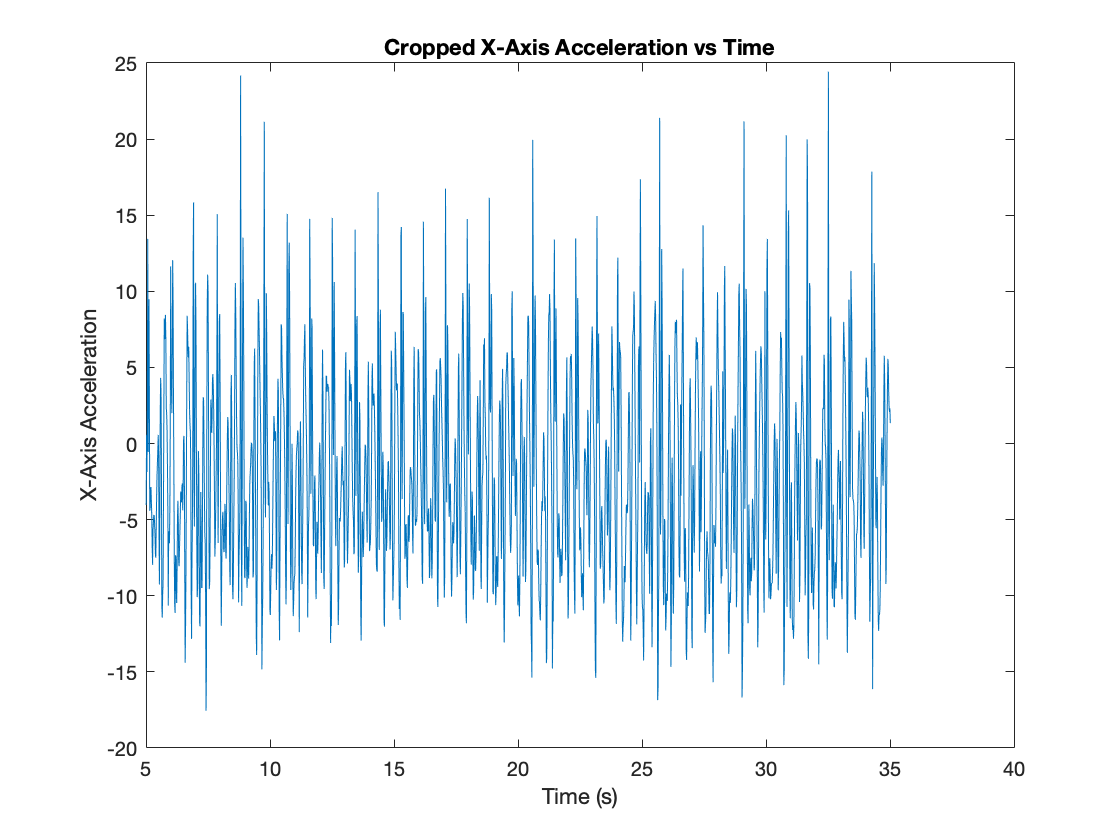

% 
%---- New Cropped WALTER Data - PLOTS -----
        
%Cropped data for x-axis acceleration vs time
plot(heelstrikeW_FINAL(:,1), heelstrikeW_FINAL(:,2));
title("Cropped X-Axis Acceleration vs Time");
xlabel("Time (s)");
ylabel("X-Axis Acceleration");

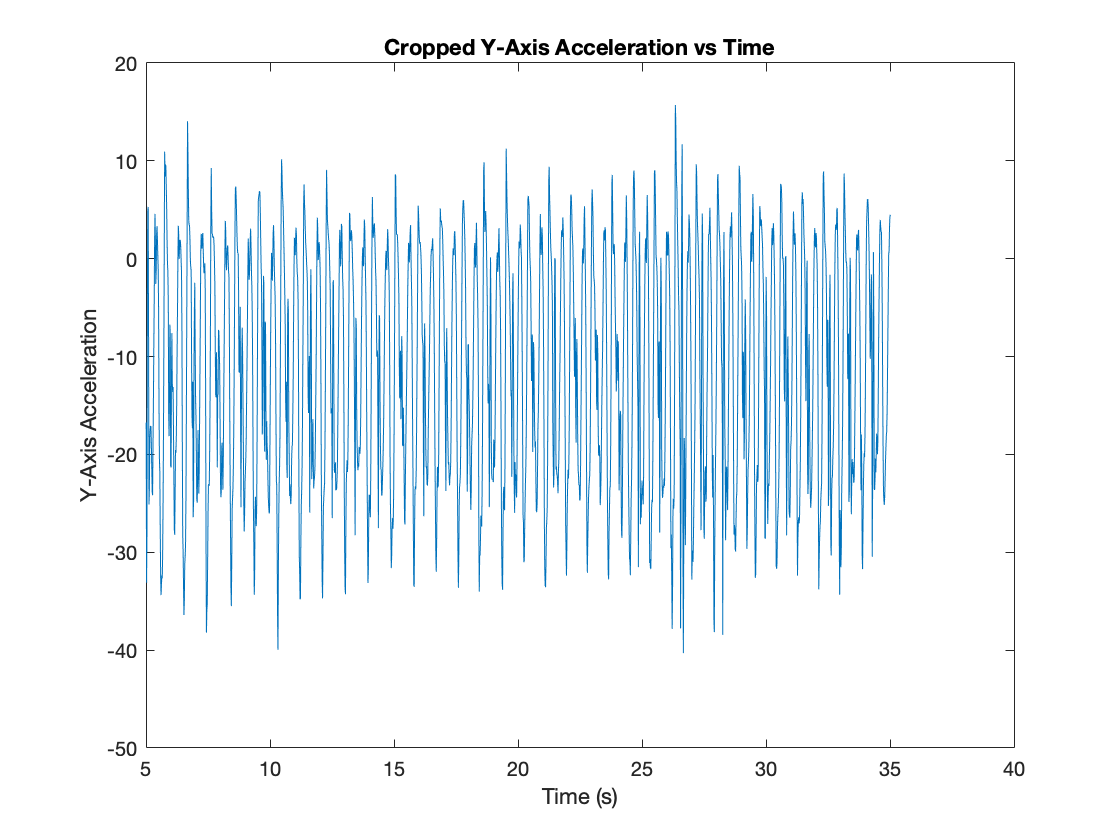



%Cropped data for y-axis acceleration vs time
plot(heelstrikeW_FINAL(:,1), heelstrikeW_FINAL(:,3));
title("Cropped Y-Axis Acceleration vs Time");
xlabel("Time (s)");
ylabel("Y-Axis Acceleration");

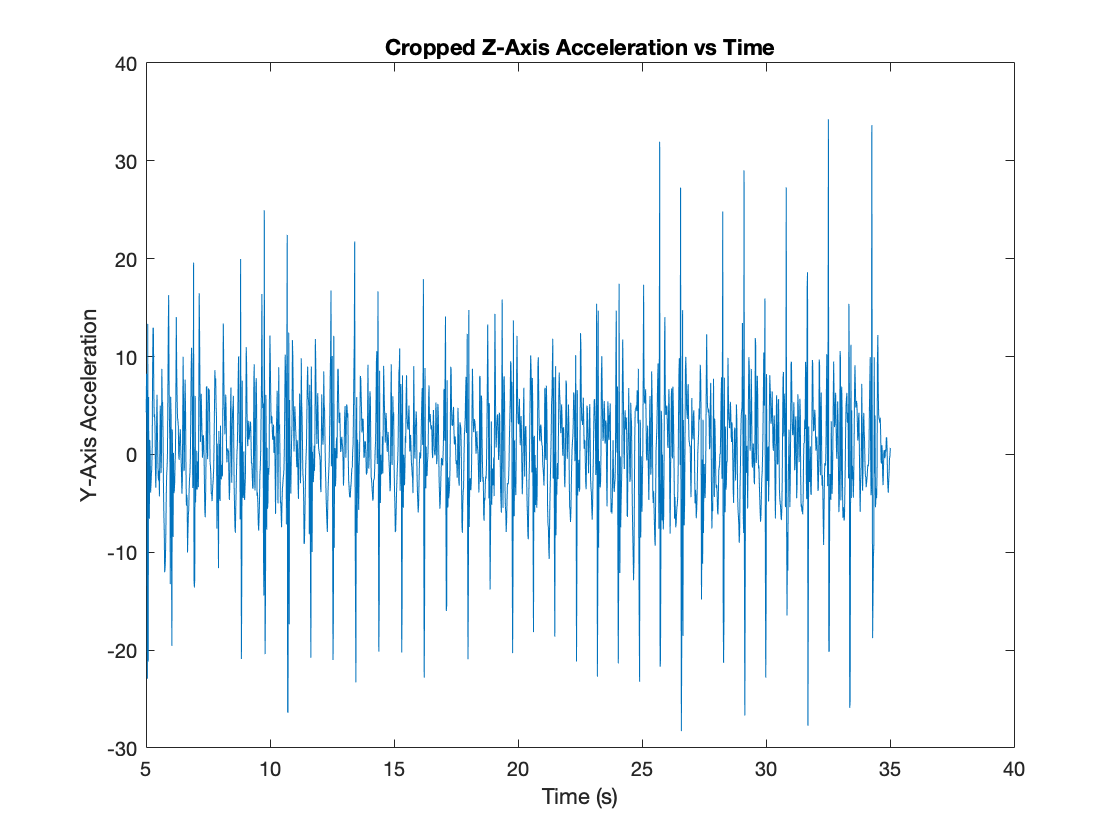


%Cropped data for z-axis acceleration vs time
plot(heelstrikeW_FINAL(:,1), heelstrikeW_FINAL(:,4));
title("Cropped Z-Axis Acceleration vs Time");
xlabel("Time (s)");
ylabel("Y-Axis Acceleration");

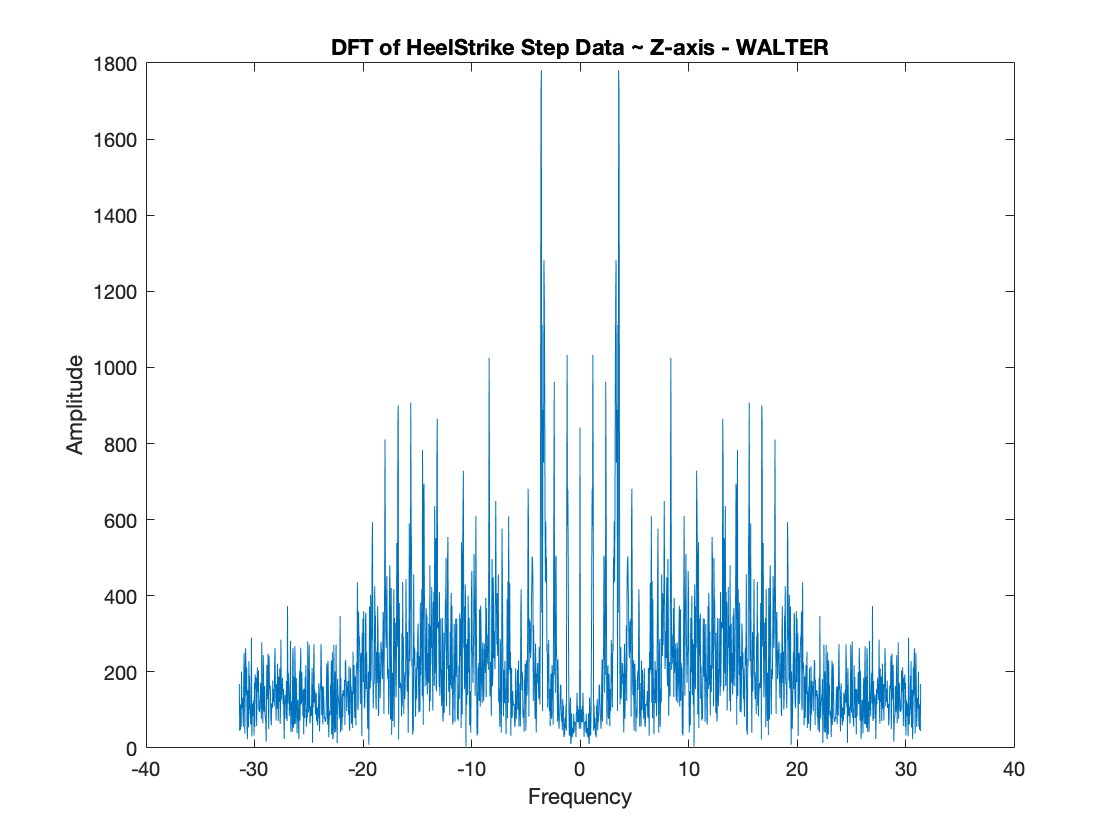



% Plotting the DFT for Z-Axis Acceleration %
P_heelstrikeW = fftshift(fft(heelstrikeW_FINAL(:,4)));
Fs = 10; %sampling frequency (Hz)
N_heelstrikeW = length(P_heelstrikeW);
F_heelstrikeW = (linspace(-pi, pi-2/N_heelstrikeW*pi, N_heelstrikeW) + pi/N_heelstrikeW*mod(N_heelstrikeW,2))* Fs; %Domain in Hertz%

% 
plot(F_heelstrikeW,abs(P_heelstrikeW')) % Plotting the DFT
title("DFT of HeelStrike Step Data ~ Z-axis - WALTER");
xlabel("Frequency");
ylabel("Amplitude");

## ToeStrike for Walter

load toestrike_walter.mat
Acceleration;

toestrikeW_timeList = Acceleration.(Acceleration.Properties.DimensionNames{1});
toestrikeW_timeInSeconds = seconds(toestrikeW_timeList - toestrikeW_timeList(1));

toestrikeW_Accel = timetable2table(Acceleration);
toestrikeW_Accel;

toestrikeW_final = table2array(toestrikeW_Accel(:,2:4));
toestrikeW_final;

toestrikeW_q = toestrikeW_timeInSeconds;

toestrikeW_finalArray = [toestrikeW_q toestrikeW_final];
toestrikeW_finalArray % <- Array that puts everything in a MATRIX

toestrikeW_finalArray =          0    1.4202    0.8053    9.5025
    0.0160    2.0022    0.5101    9.4466
    0.0320    1.8397    0.4200    9.8640
    0.0480    1.4202    0.7757   10.4355
    0.0650    1.1635    0.8791    9.9856
    0.0810    0.8032    0.1744    9.0366
    0.0970    0.7526    0.3907    9.6880
    0.1130    0.1016    0.4865    9.0030
    0.1290    0.0509    0.6995    8.4625
    0.1460    0.5977    0.5341    8.6640


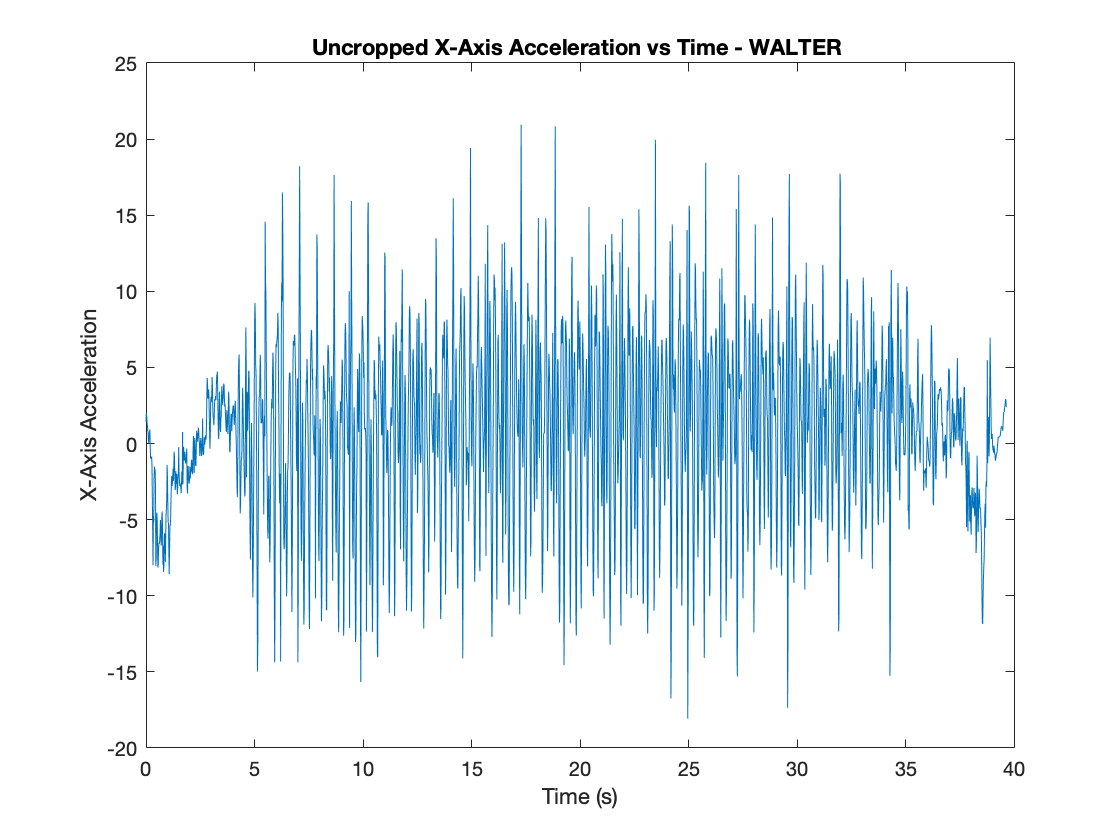


% toestrikeW_xaxis;
plot(toestrikeW_finalArray(:,1), toestrikeW_finalArray(:,2));
title("Uncropped X-Axis Acceleration vs Time - WALTER ");
xlabel("Time (s)");
ylabel("X-Axis Acceleration");

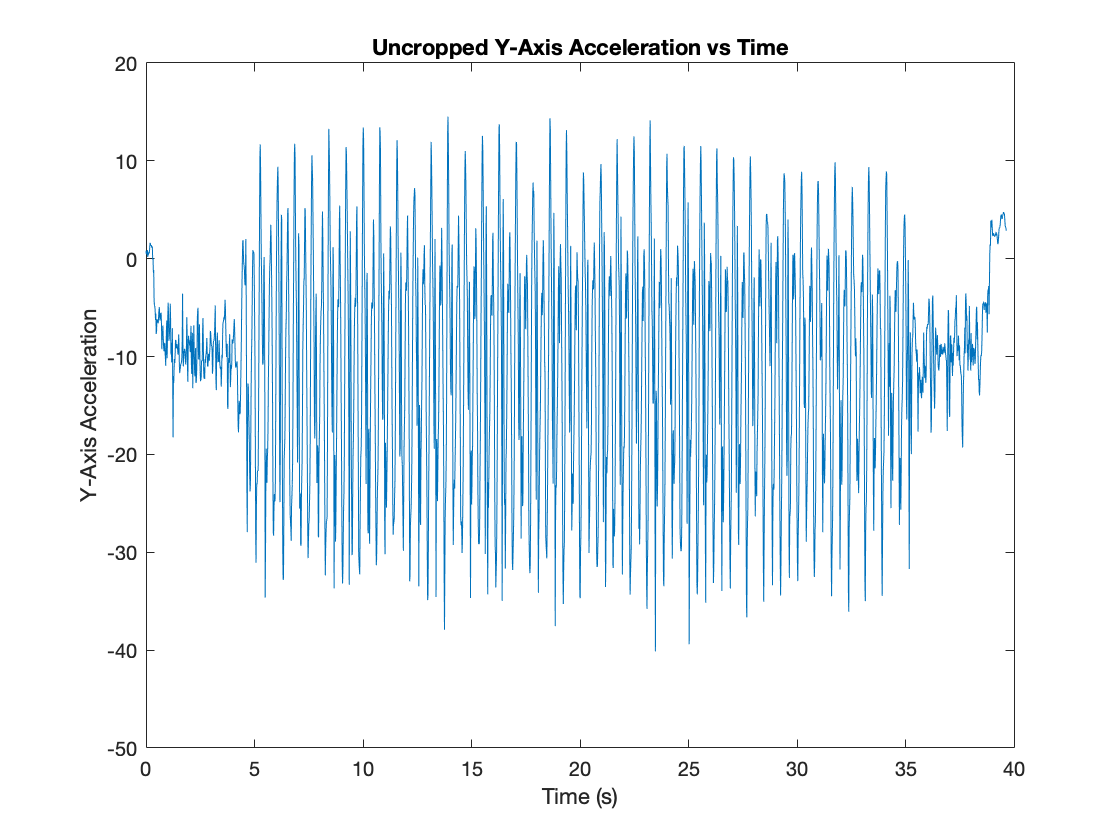


% toestrikeW_yaxis;
plot(toestrikeW_finalArray(:,1), toestrikeW_finalArray(:,3));
title("Uncropped Y-Axis Acceleration vs Time");
xlabel("Time (s)");
ylabel("Y-Axis Acceleration");

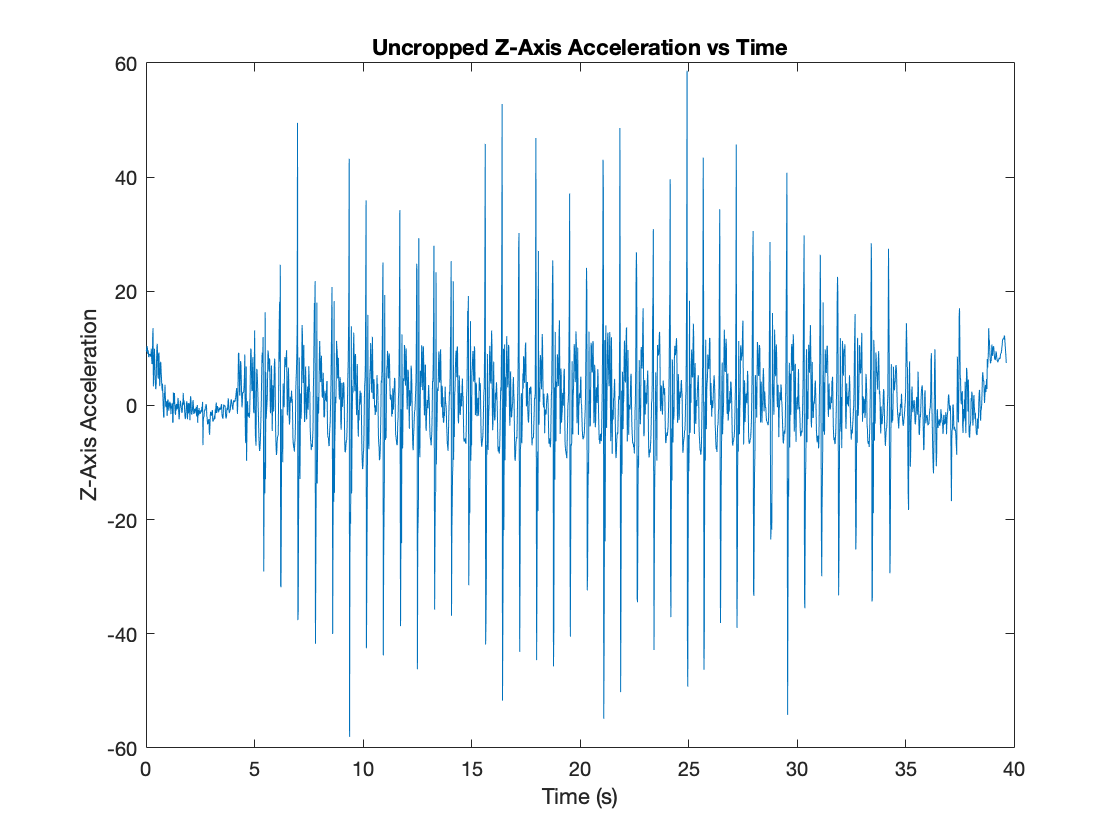


% toestrikeW_zaxis;
plot(toestrikeW_finalArray(:,1), toestrikeW_finalArray(:,4));
title("Uncropped Z-Axis Acceleration vs Time");
xlabel("Time (s)");
ylabel("Z-Axis Acceleration");


 
% UNIMPORTANT - USED TO FIGURE OUT INDEX  -->  plot(midfoot_finalArray(751:1376, 1), midfoot_finalArray(751:1376, 4)); % z acceleration vs time (CROPPED) NEED TO CHANGE THE SCALE (?)
% Crop data at t = 5.0060 - 35.0120
% V = valid data that we can use
VtoestrikeW_time_data = toestrikeW_finalArray(310:2162, 1);
VtoestrikeW_xaxis_data = toestrikeW_finalArray(310:2162, 2);
VtoestrikeW_yaxis_data = toestrikeW_finalArray(310:2162, 3);
VtoestrikeW_zaxis_data = toestrikeW_finalArray(310:2162, 4);

% new array for midfootStep data
toestrikeW_FINAL = [VtoestrikeW_time_data VtoestrikeW_xaxis_data VtoestrikeW_yaxis_data VtoestrikeW_zaxis_data] % <==== THIS IS THE DATA ARRAY THAT WE ARE USING

toestrikeW_FINAL =     5.0060    8.0447   -6.1592   13.1695
    5.0220    9.2368  -10.4092    5.0324
    5.0390    8.0947  -18.9645   -5.0599
    5.0550    5.1119  -28.3223   -6.0917
    5.0710    4.6850  -31.0706   -7.0575
    5.0870    1.3259  -25.5192    1.8599
    5.1030   -2.2681  -22.9594    6.4196
    5.1200   -9.0030  -23.0875    6.0774
    5.1360  -14.9835  -21.7707    4.3068
    5.1520  -13.4587  -21.6444    2.4817


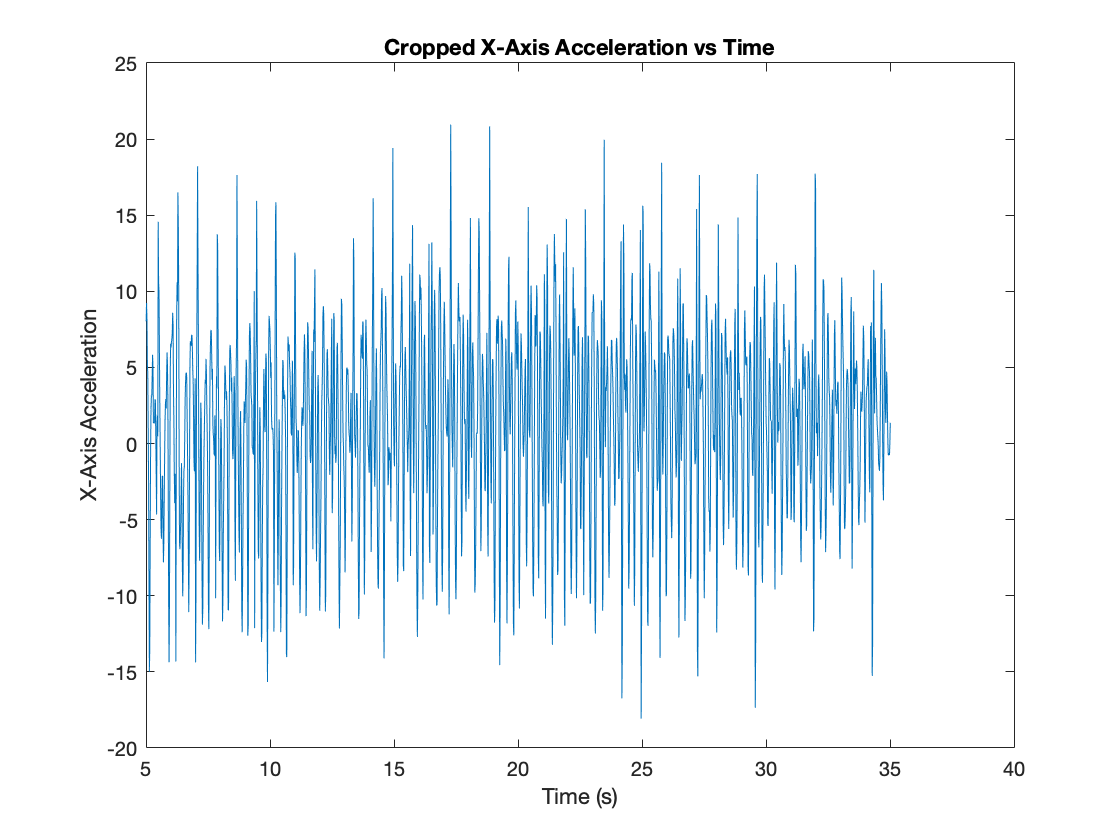

% 
% %---- New Cropped WALTER Data - PLOTS -----
        
%Cropped data for x-axis acceleration vs time
plot(toestrikeW_FINAL(:,1), toestrikeW_FINAL(:,2));
title("Cropped X-Axis Acceleration vs Time");
xlabel("Time (s)");
ylabel("X-Axis Acceleration");

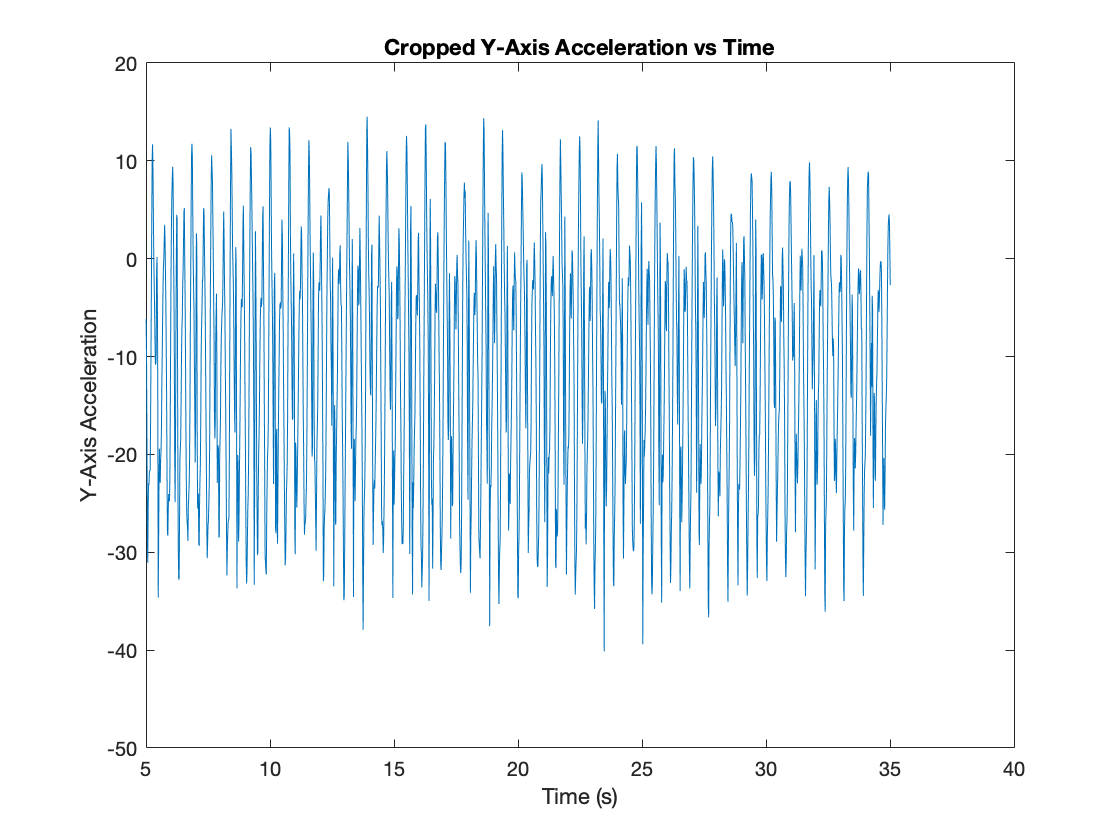



%Cropped data for y-axis acceleration vs time
plot(toestrikeW_FINAL(:,1), toestrikeW_FINAL(:,3));
title("Cropped Y-Axis Acceleration vs Time");
xlabel("Time (s)");
ylabel("Y-Axis Acceleration");

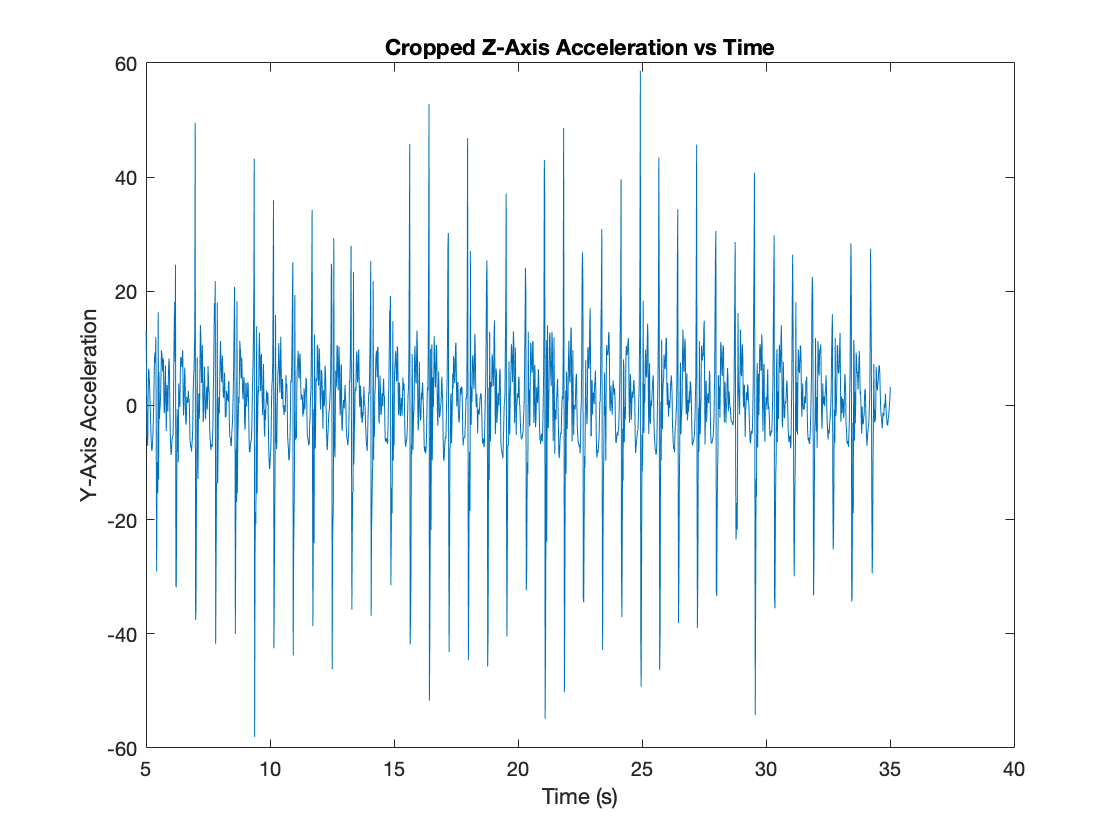


%Cropped data for z-axis acceleration vs time
plot(toestrikeW_FINAL(:,1), toestrikeW_FINAL(:,4));
title("Cropped Z-Axis Acceleration vs Time");
xlabel("Time (s)");
ylabel("Y-Axis Acceleration");

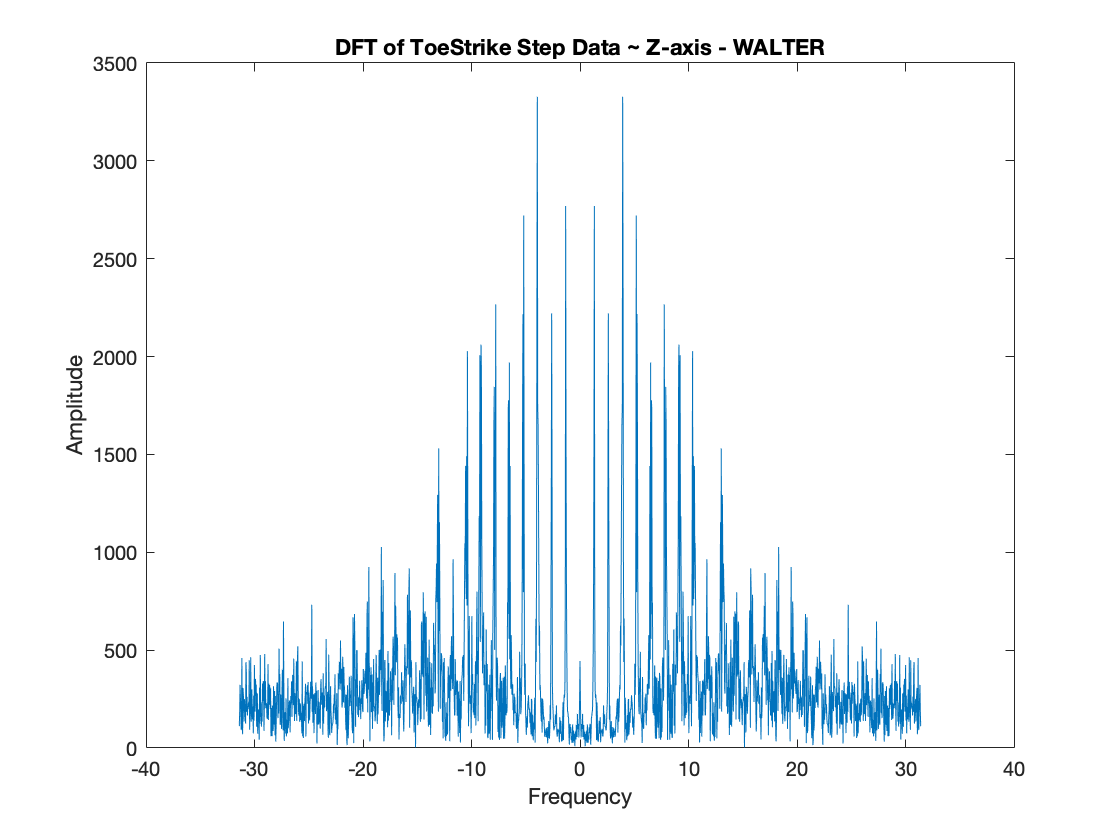



% Plotting the DFT for Z-Axis Acceleration %
P_toestrikeW = fftshift(fft(toestrikeW_FINAL(:,4)));
Fs = 10; %sampling frequency (Hz)
N_toestrikeW = length(P_toestrikeW);
F_toestrikeW = (linspace(-pi, pi-2/N_toestrikeW*pi, N_toestrikeW) + pi/N_toestrikeW*mod(N_toestrikeW,2))* Fs; %Domain in Hertz%

% 
plot(F_toestrikeW,abs(P_toestrikeW')) % Plotting the DFT
title("DFT of ToeStrike Step Data ~ Z-axis - WALTER");
xlabel("Frequency");
ylabel("Amplitude");

## Final Round - Collecting Data from WALTER - MIDSTRIKE

load LASTmidstrike_walter.mat;

Acceleration;

FINALmidstrike_timeList = Acceleration.(Acceleration.Properties.DimensionNames{1});
FINALmidstrike_timeInSeconds = seconds(FINALmidstrike_timeList - FINALmidstrike_timeList(1));

FINALmidstrike_Accel = timetable2table(Acceleration);
FINALmidstrike_Accel;

FINALmidstrike_final = table2array(FINALmidstrike_Accel(:,2:4));
FINALmidstrike_final;

FINALmidstrike_q = FINALmidstrike_timeInSeconds;

FINALmidstrike_finalArray = [FINALmidstrike_q FINALmidstrike_final];
FINALmidstrike_finalArray % <- Array that puts everything in a MATRIX

FINALmidstrike_finalArray =          0   -1.8551    0.5537    9.6142
    0.0160   -1.6990    0.4371    9.1367
    0.0320   -0.8499    0.5925    8.7029
    0.0480   -0.6182    0.6492    8.8568
    0.0650   -0.5115    0.8180    9.0888
    0.0810   -0.6363    0.8633    9.3916
    0.0970   -0.8531    0.7522    9.2382
    0.1130   -0.7902    0.6513    9.3570
    0.1290   -0.4325    0.4682    9.5868
    0.1460   -0.3814    0.9357    9.2220


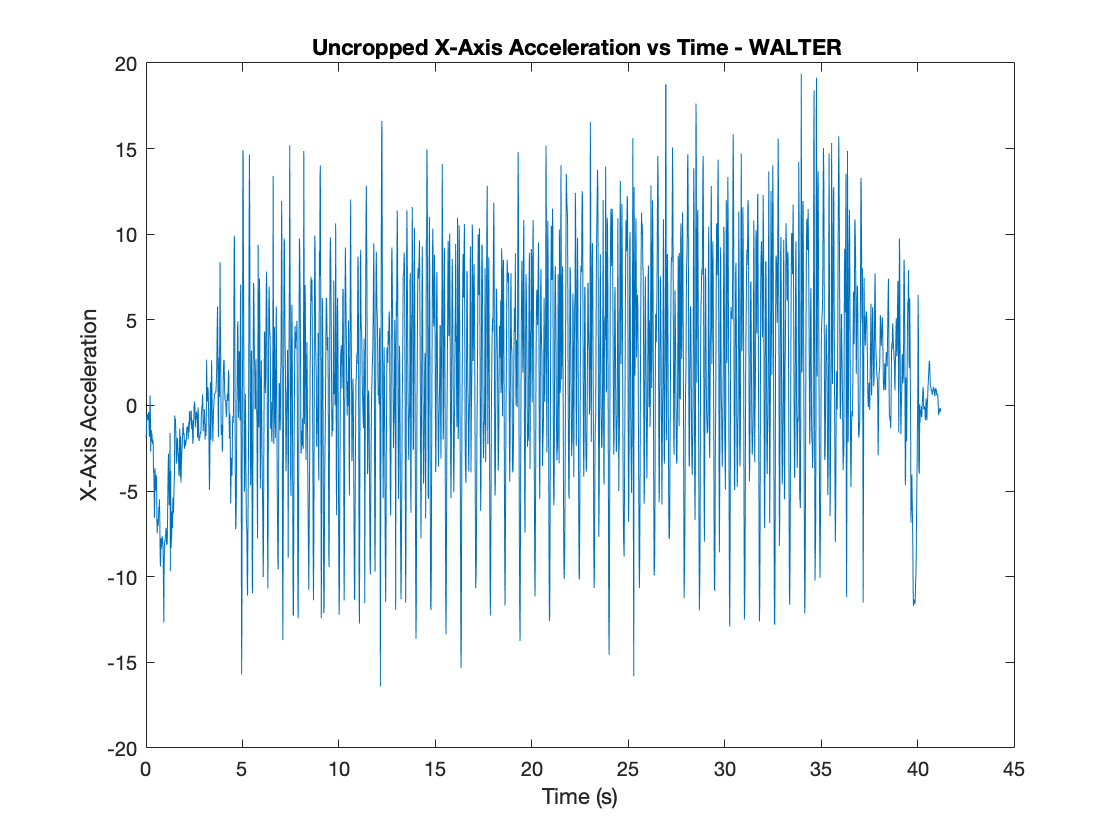


% FINALmidstrike_xaxis;
plot(FINALmidstrike_finalArray(:,1), FINALmidstrike_finalArray(:,2));
title("Uncropped X-Axis Acceleration vs Time - WALTER ");
xlabel("Time (s)");
ylabel("X-Axis Acceleration");

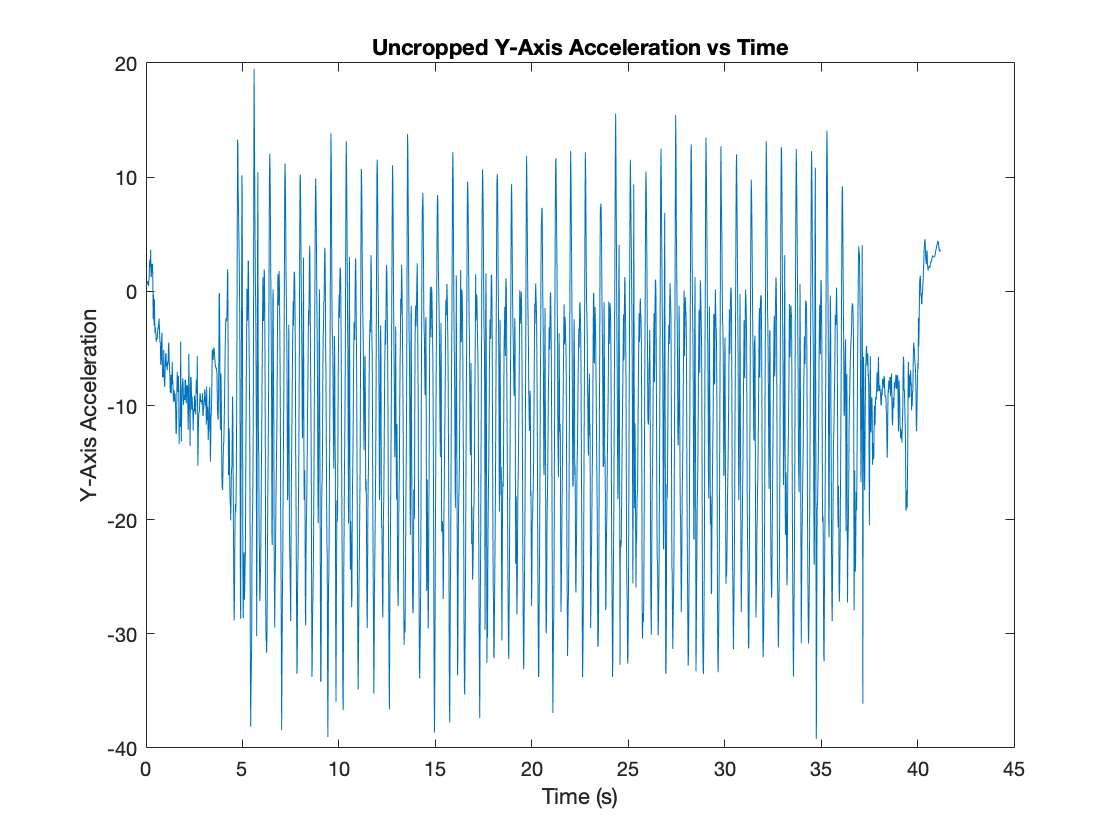


% FINALmidstrike_yaxis;
plot(FINALmidstrike_finalArray(:,1), FINALmidstrike_finalArray(:,3));
title("Uncropped Y-Axis Acceleration vs Time");
xlabel("Time (s)");
ylabel("Y-Axis Acceleration");

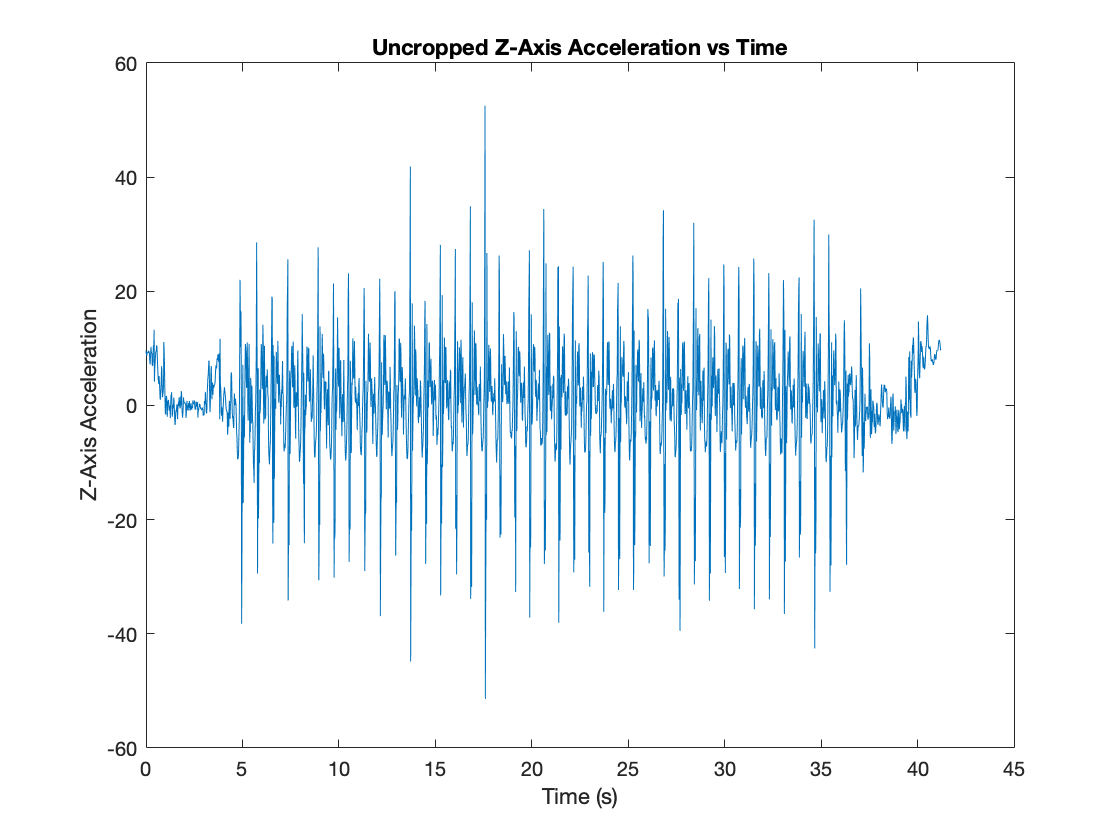


% FINALmidstrike_zaxis;
plot(FINALmidstrike_finalArray(:,1), FINALmidstrike_finalArray(:,4));
title("Uncropped Z-Axis Acceleration vs Time");
xlabel("Time (s)");
ylabel("Z-Axis Acceleration");


% UNIMPORTANT - USED TO FIGURE OUT INDEX  -->  plot(midfoot_finalArray(751:1376, 1), midfoot_finalArray(751:1376, 4)); % z acceleration vs time (CROPPED) NEED TO CHANGE THE SCALE (?)
% Crop data at t = 5.99 (almost 6) - 36.0130
% V = valid data that we can use
VFINALmidstrike_time_data = FINALmidstrike_finalArray(371:2224, 1);
VFINALmidstrike_xaxis_data = FINALmidstrike_finalArray(371:2224, 2);
VFINALmidstrike_yaxis_data = FINALmidstrike_finalArray(371:2224, 3);
VFINALmidstrike_zaxis_data = FINALmidstrike_finalArray(371:2224, 4);

% new array for midfootStep data
FINALmidstrike_FINAL = [VFINALmidstrike_time_data VFINALmidstrike_xaxis_data VFINALmidstrike_yaxis_data VFINALmidstrike_zaxis_data] % <==== THIS IS THE DATA ARRAY THAT WE ARE USING

FINALmidstrike_FINAL =     5.9940    0.2994  -13.7363    9.1810
    6.0100   -2.3350   -9.9293    7.1705
    6.0260   -3.9479   -5.9468    2.8462
    6.0430   -5.4413   -2.1533    5.0132
    6.0590   -7.0602    1.1959   14.1480
    6.0750  -10.0194   -2.1272   11.4311
    6.0910   -8.3920   -2.6010    1.3711
    6.1070   -3.0879   -1.3731   -3.1474
    6.1240    0.3750    1.9151    3.7281
    6.1400    4.3202    1.6362   10.4680


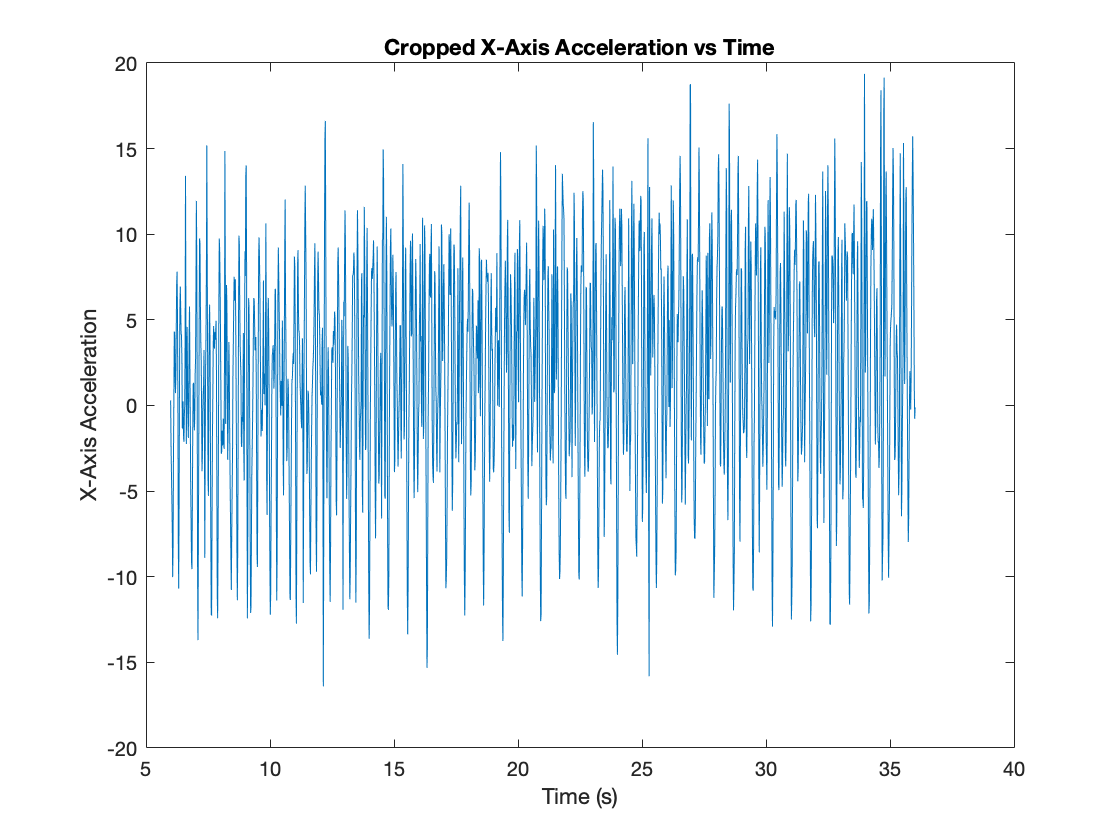


% %---- New Cropped WALTER Data - PLOTS -----
        
%Cropped data for x-axis acceleration vs time
plot(FINALmidstrike_FINAL(:,1), FINALmidstrike_FINAL(:,2));
title("Cropped X-Axis Acceleration vs Time");
xlabel("Time (s)");
ylabel("X-Axis Acceleration");

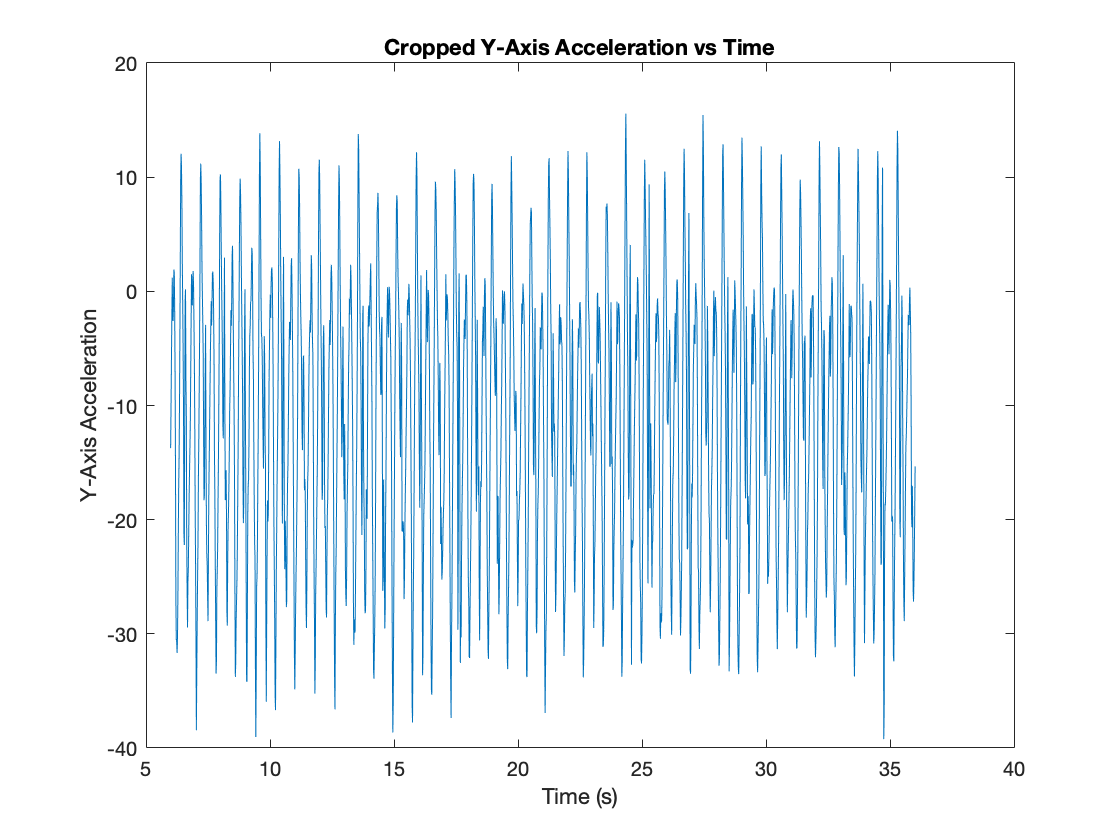



%Cropped data for y-axis acceleration vs time
plot(FINALmidstrike_FINAL(:,1), FINALmidstrike_FINAL(:,3));
title("Cropped Y-Axis Acceleration vs Time");
xlabel("Time (s)");
ylabel("Y-Axis Acceleration");

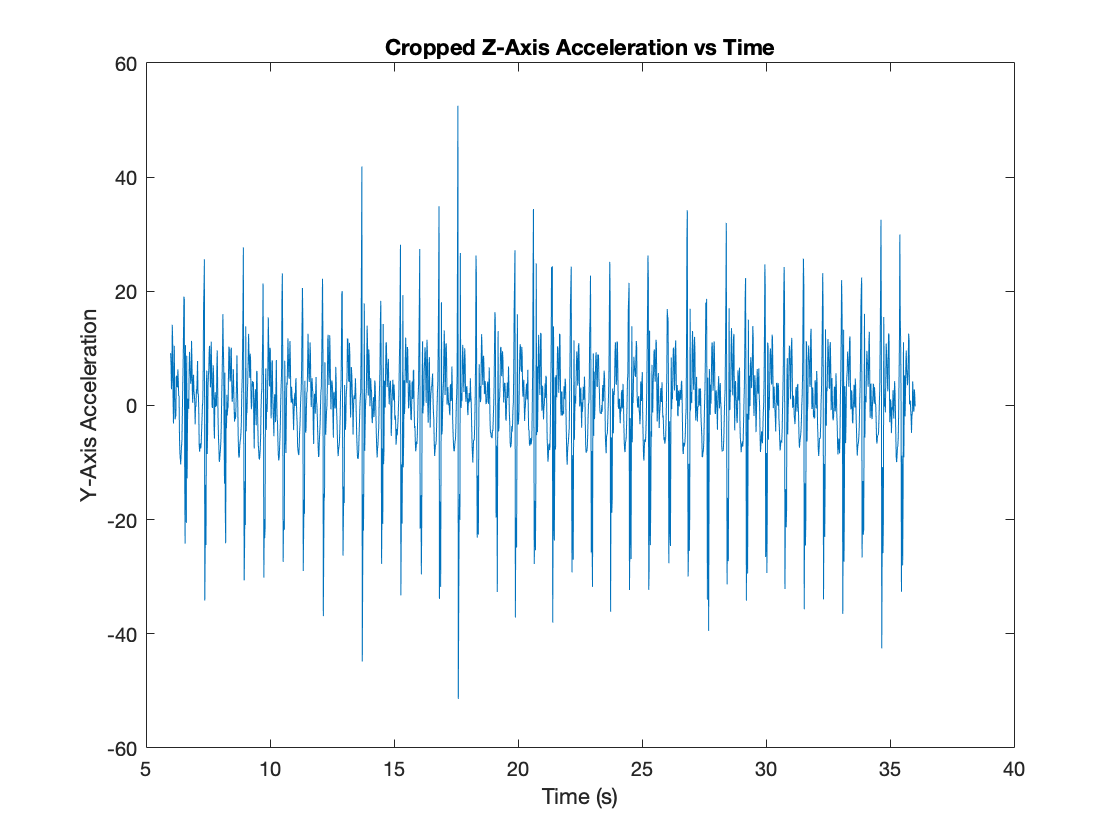


%Cropped data for z-axis acceleration vs time
plot(FINALmidstrike_FINAL(:,1), FINALmidstrike_FINAL(:,4));
title("Cropped Z-Axis Acceleration vs Time");
xlabel("Time (s)");
ylabel("Y-Axis Acceleration");

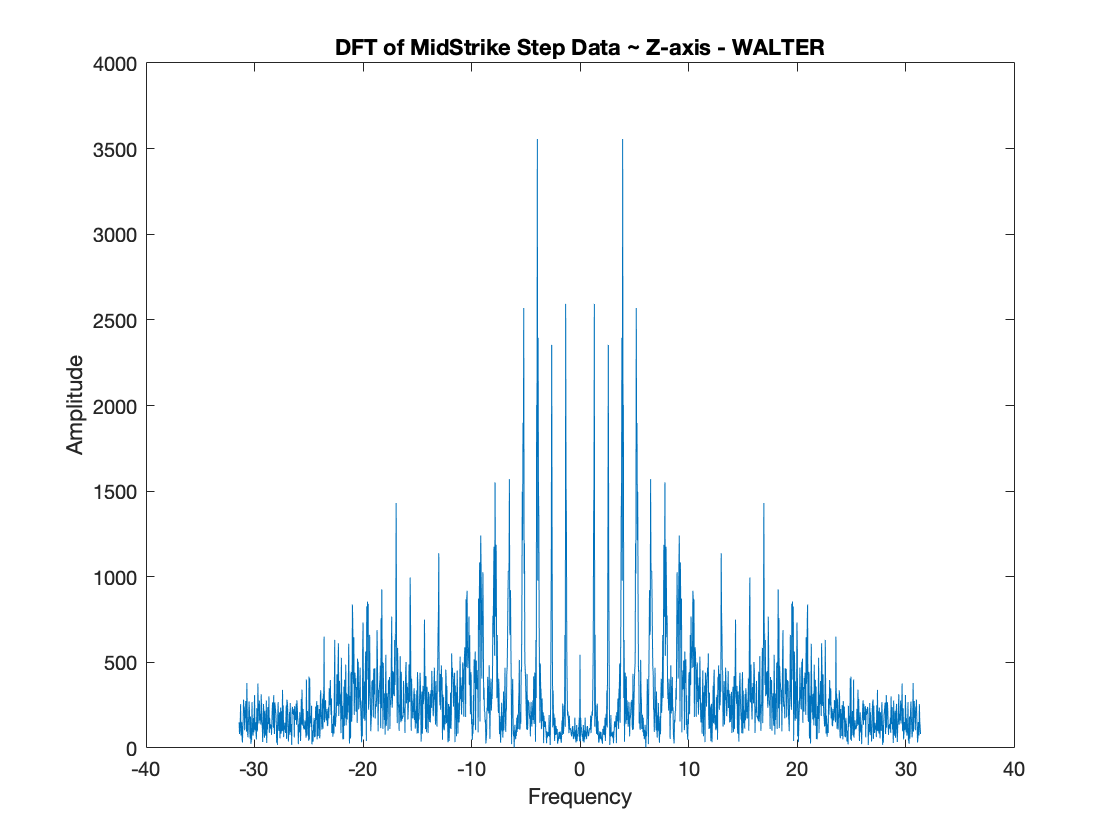



% Plotting the DFT for Z-Axis Acceleration %
P_FINALmidstrike = fftshift(fft(FINALmidstrike_FINAL(:,4)));
Fs = 10; %sampling frequency (Hz)
N_FINALmidstrike = length(P_FINALmidstrike);
F_FINALmidstrike = (linspace(-pi, pi-2/N_FINALmidstrike*pi, N_FINALmidstrike) + pi/N_FINALmidstrike*mod(N_FINALmidstrike,2))* Fs; %Domain in Hertz%


plot(F_FINALmidstrike,abs(P_FINALmidstrike')) % Plotting the DFT
title("DFT of MidStrike Step Data ~ Z-axis - WALTER");
xlabel("Frequency");
ylabel("Amplitude");

## Final Round - Collecting Data From Walter - HEELSTEP

load LASTheelstrike_walter.mat;

Acceleration;

FINALheelstrike_timeList = Acceleration.(Acceleration.Properties.DimensionNames{1});
FINALheelstrike_timeInSeconds = seconds(FINALheelstrike_timeList - FINALheelstrike_timeList(1));

FINALheelstrike_Accel = timetable2table(Acceleration);
FINALheelstrike_Accel;

FINALheelstrike_final = table2array(FINALheelstrike_Accel(:,2:4));
FINALheelstrike_final;

FINALheelstrike_q = FINALheelstrike_timeInSeconds;

FINALheelstrike_finalArray = [FINALheelstrike_q FINALheelstrike_final];
FINALheelstrike_finalArray % <- Array that puts everything in a MATRIX

FINALheelstrike_finalArray =          0   -1.0008    2.8995    7.9530
    0.0170   -0.5242    2.9558    8.4278
    0.0330    0.3242    2.5543    9.6299
    0.0490    1.0290    2.1199    9.3376
    0.0650    1.0793    2.1465    9.0548
    0.0810    0.3831    2.5426    8.2682
    0.0980    0.1422    2.6219    7.8714
    0.1140    0.3055    3.0652    6.9667
    0.1300    1.1272    3.5654    6.6695
    0.1460    0.4766    3.8639    7.3979


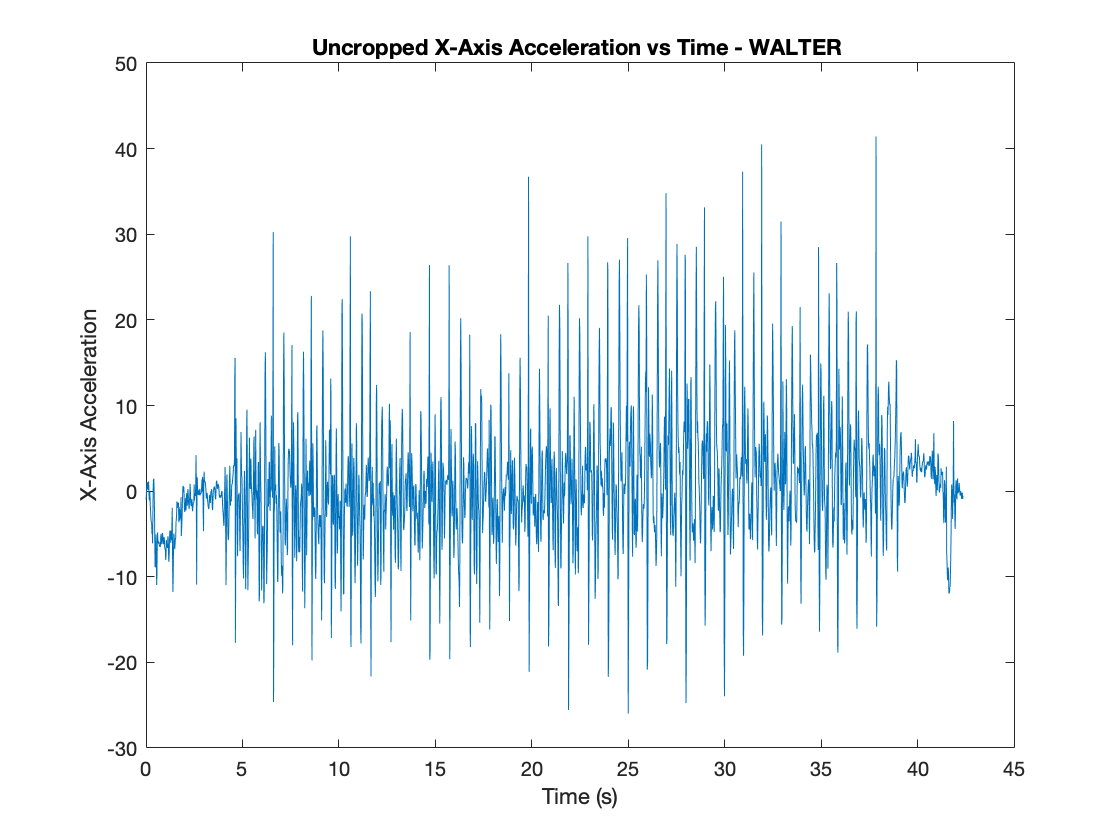


% FINALheelstrike_xaxis;
plot(FINALheelstrike_finalArray(:,1), FINALheelstrike_finalArray(:,2));
title("Uncropped X-Axis Acceleration vs Time - WALTER ");
xlabel("Time (s)");
ylabel("X-Axis Acceleration");

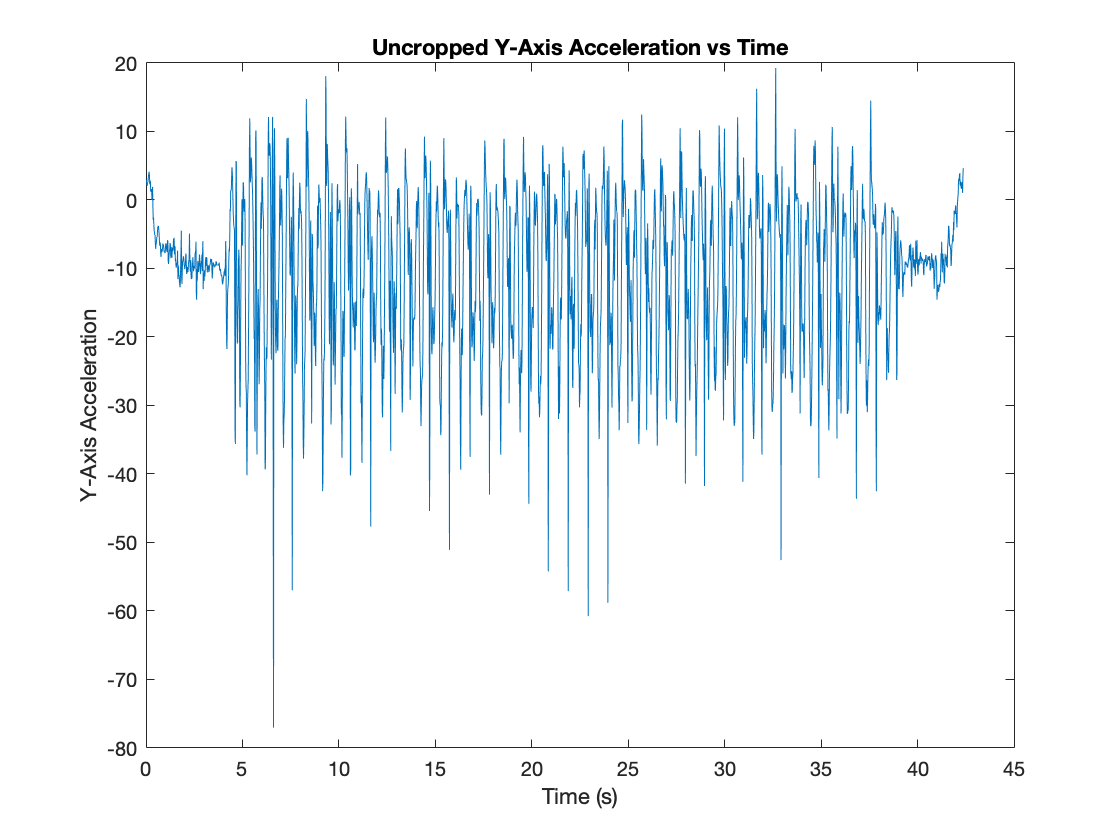


% FINALheelstrike_yaxis;
plot(FINALheelstrike_finalArray(:,1), FINALheelstrike_finalArray(:,3));
title("Uncropped Y-Axis Acceleration vs Time");
xlabel("Time (s)");
ylabel("Y-Axis Acceleration");

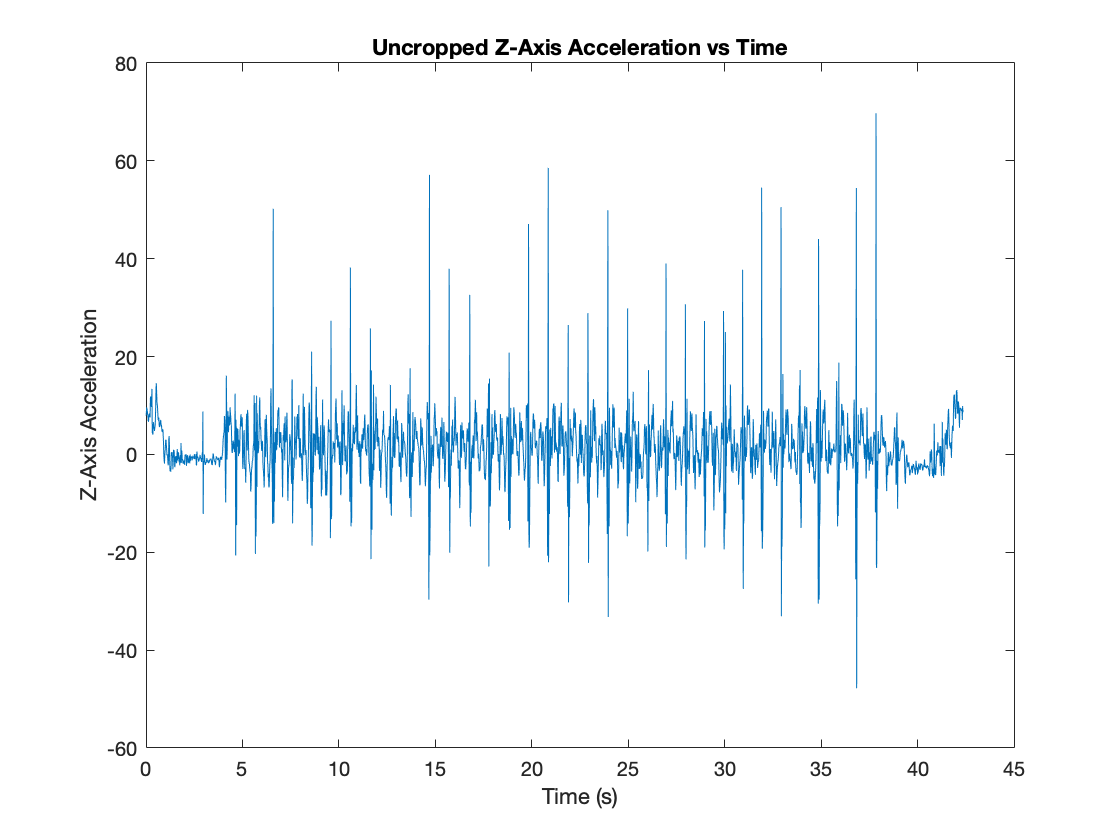


% FINALheelstrike_zaxis;
plot(FINALheelstrike_finalArray(:,1), FINALheelstrike_finalArray(:,4));
title("Uncropped Z-Axis Acceleration vs Time");
xlabel("Time (s)");
ylabel("Z-Axis Acceleration");





% UNIMPORTANT - USED TO FIGURE OUT INDEX -->  plot(midfoot_finalArray(751:1376, 1), midfoot_finalArray(751:1376, 4)); % z acceleration vs time (CROPPED) NEED TO CHANGE THE SCALE (?)
% Crop data at t = 8.004 - 38.01
% V = valid data that we can use
VFINALheelstrike_time_data = FINALheelstrike_finalArray(495:2347, 1);
VFINALheelstrike_xaxis_data = FINALheelstrike_finalArray(495:2347, 2);
VFINALheelstrike_yaxis_data = FINALheelstrike_finalArray(495:2347, 3);
VFINALheelstrike_zaxis_data = FINALheelstrike_finalArray(495:2347, 4);

% new array for midfootStep data
FINALheelstrike_FINAL = [VFINALheelstrike_time_data VFINALheelstrike_xaxis_data VFINALheelstrike_yaxis_data VFINALheelstrike_zaxis_data] % <==== THIS IS THE DATA ARRAY THAT WE ARE USING

FINALheelstrike_FINAL =     8.0040   -1.9569   -1.2442    3.0191
    8.0210   -1.1435   -1.9874   -0.5019
    8.0370   -1.0258   -1.5699   -0.7541
    8.0530   -0.2977   -2.2863    0.2699
    8.0690    0.8800   -3.4927   -0.5697
    8.0850   -1.8799   -8.4932   -3.4996
    8.1020   -8.8408  -16.6017   -5.4304
    8.1180  -11.7345  -25.8631   -3.4892
    8.1340   -1.5575  -28.2757    3.7286
    8.1500   12.8054  -35.2488   12.4161


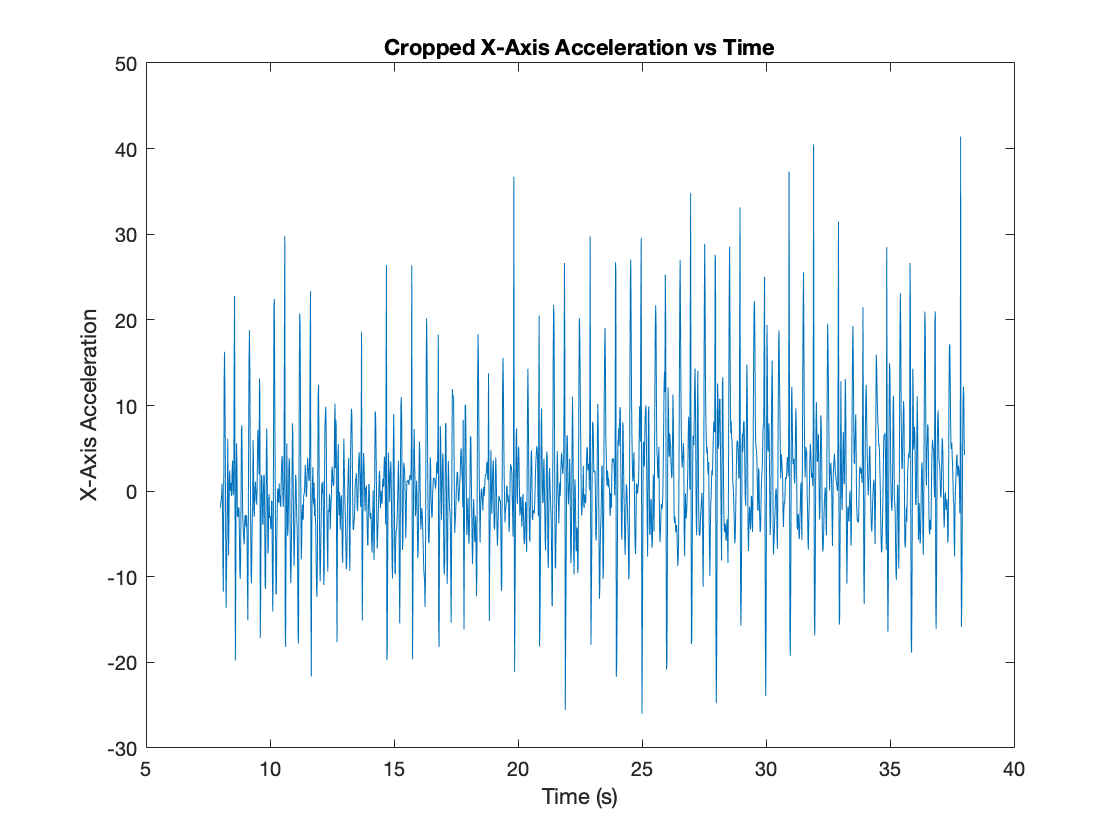


% %---- New Cropped WALTER Data - PLOTS -----
        
%Cropped data for x-axis acceleration vs time
plot(FINALheelstrike_FINAL(:,1), FINALheelstrike_FINAL(:,2));
title("Cropped X-Axis Acceleration vs Time");
xlabel("Time (s)");
ylabel("X-Axis Acceleration");

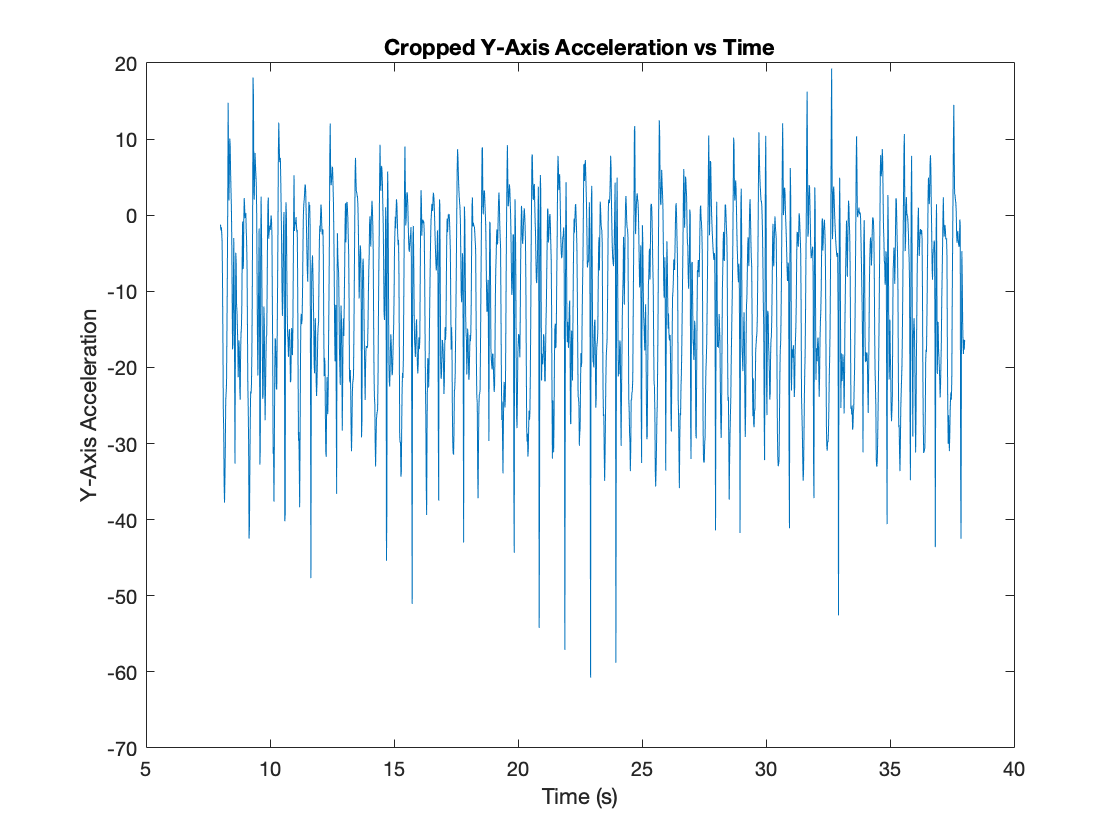



%Cropped data for y-axis acceleration vs time
plot(FINALheelstrike_FINAL(:,1), FINALheelstrike_FINAL(:,3));
title("Cropped Y-Axis Acceleration vs Time");
xlabel("Time (s)");
ylabel("Y-Axis Acceleration");

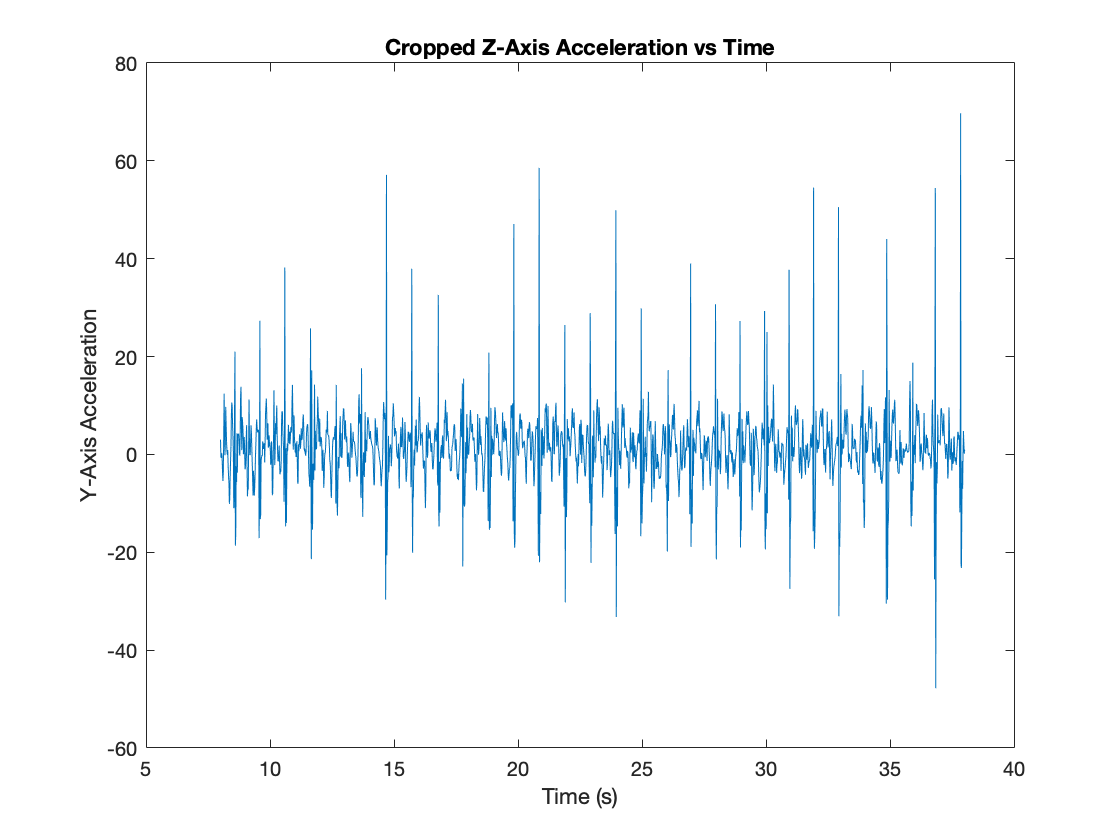


%Cropped data for z-axis acceleration vs time
plot(FINALheelstrike_FINAL(:,1), FINALheelstrike_FINAL(:,4));
title("Cropped Z-Axis Acceleration vs Time");
xlabel("Time (s)");
ylabel("Y-Axis Acceleration");

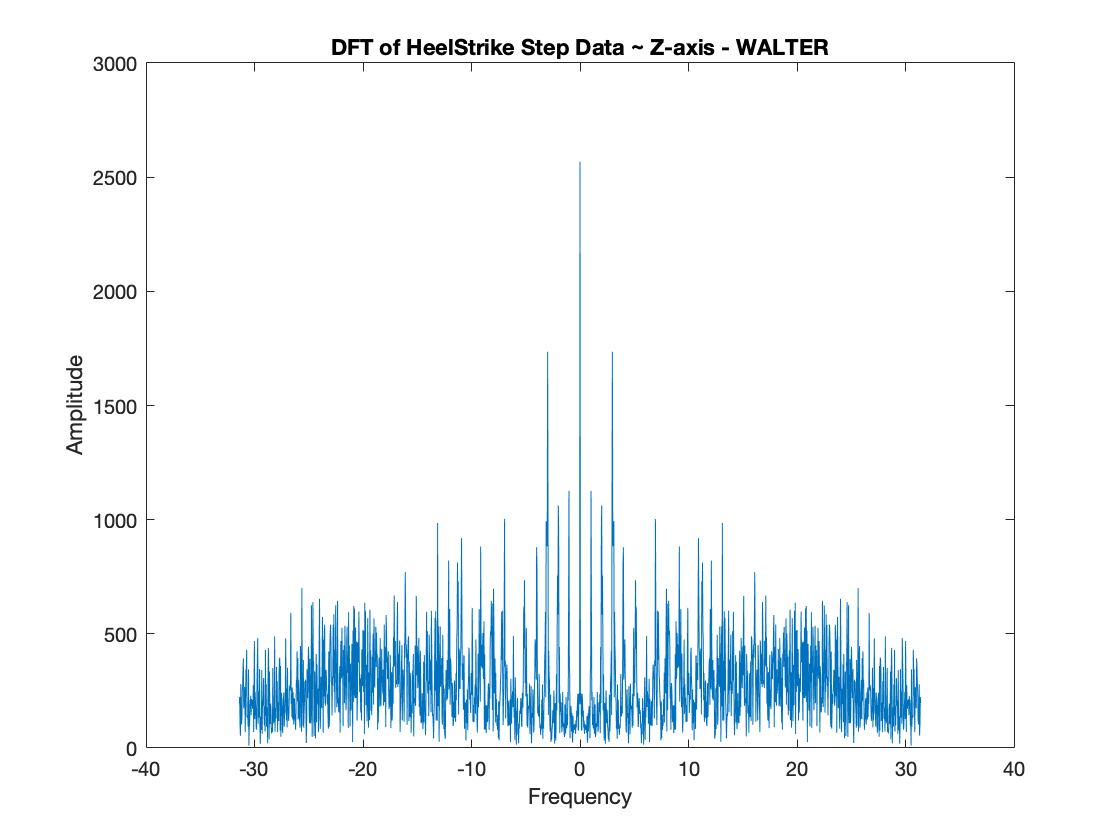



% Plotting the DFT for Z-Axis Acceleration %
P_FINALheelstrike = fftshift(fft(FINALheelstrike_FINAL(:,4)));
Fs = 10; %sampling frequency (Hz)
N_FINALheelstrike = length(P_FINALheelstrike);
F_FINALheelstrike = (linspace(-pi, pi-2/N_FINALheelstrike*pi, N_FINALheelstrike) + pi/N_FINALheelstrike*mod(N_FINALheelstrike,2))* Fs; %Domain in Hertz%


plot(F_FINALheelstrike,abs(P_FINALheelstrike')) % Plotting the DFT
title("DFT of HeelStrike Step Data ~ Z-axis - WALTER");
xlabel("Frequency");
ylabel("Amplitude");

## Final Round - Collecting Data From Walter - TOESTEP

load LASTtoestrike_walter.mat;

Acceleration;

FINALtoestrike_timeList = Acceleration.(Acceleration.Properties.DimensionNames{1});
FINALtoestrike_timeInSeconds = seconds(FINALtoestrike_timeList - FINALtoestrike_timeList(1));

FINALtoestrike_Accel = timetable2table(Acceleration);
FINALtoestrike_Accel;

FINALtoestrike_final = table2array(FINALtoestrike_Accel(:,2:4));
FINALtoestrike_final;

FINALtoestrike_q = FINALtoestrike_timeInSeconds;

FINALtoestrike_finalArray = [FINALtoestrike_q FINALtoestrike_final];
FINALtoestrike_finalArray % <- Array that puts everything in a MATRIX

FINALtoestrike_finalArray =          0   -0.4413    1.8757    9.3531
    0.0160   -0.3738    1.8957    9.2121
    0.0320   -0.5172    1.8805    9.3279
    0.0480   -0.4884    1.7957    9.4078
    0.0640   -0.2479    1.8192    9.3488
    0.0810    0.0710    1.9570    9.0084
    0.0970   -0.0124    2.1411    8.4305
    0.1130   -0.5377    2.4297    7.7370
    0.1290   -0.8514    2.3546    6.8511
    0.1450   -0.9348    3.0710    6.2673


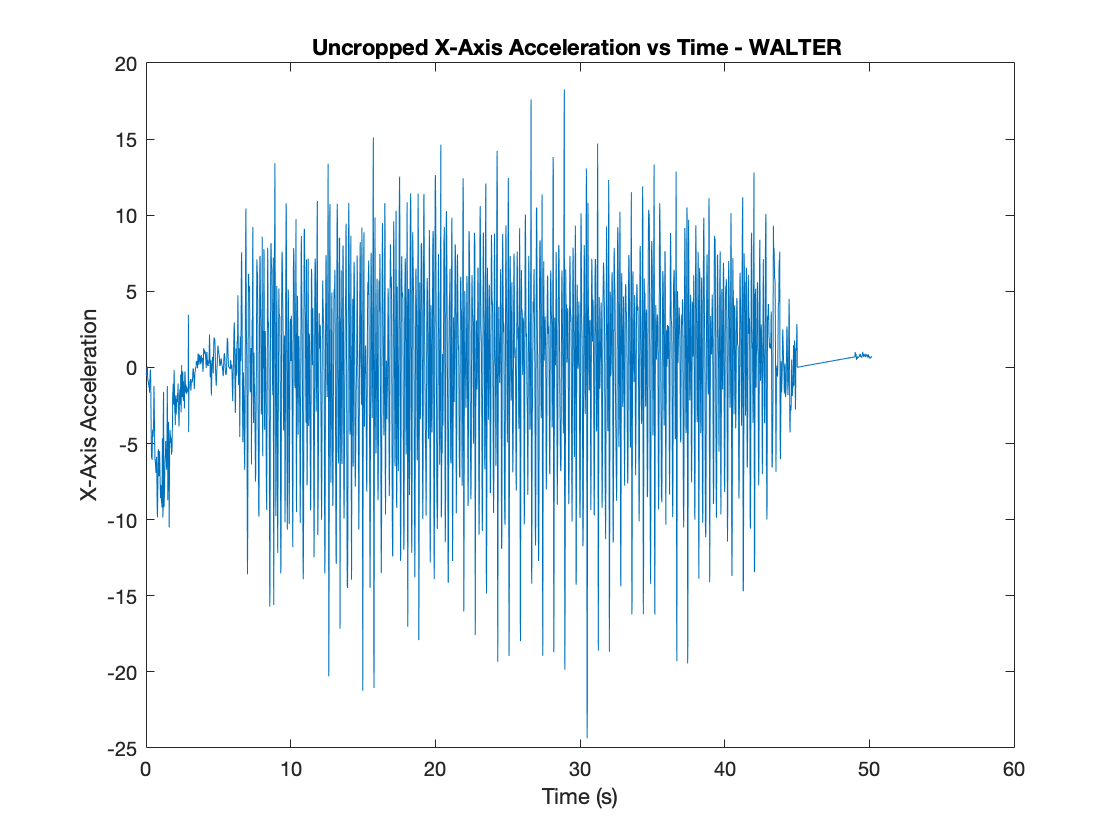


% FINALtoestrike_xaxis;
plot(FINALtoestrike_finalArray(:,1), FINALtoestrike_finalArray(:,2));
title("Uncropped X-Axis Acceleration vs Time - WALTER ");
xlabel("Time (s)");
ylabel("X-Axis Acceleration");

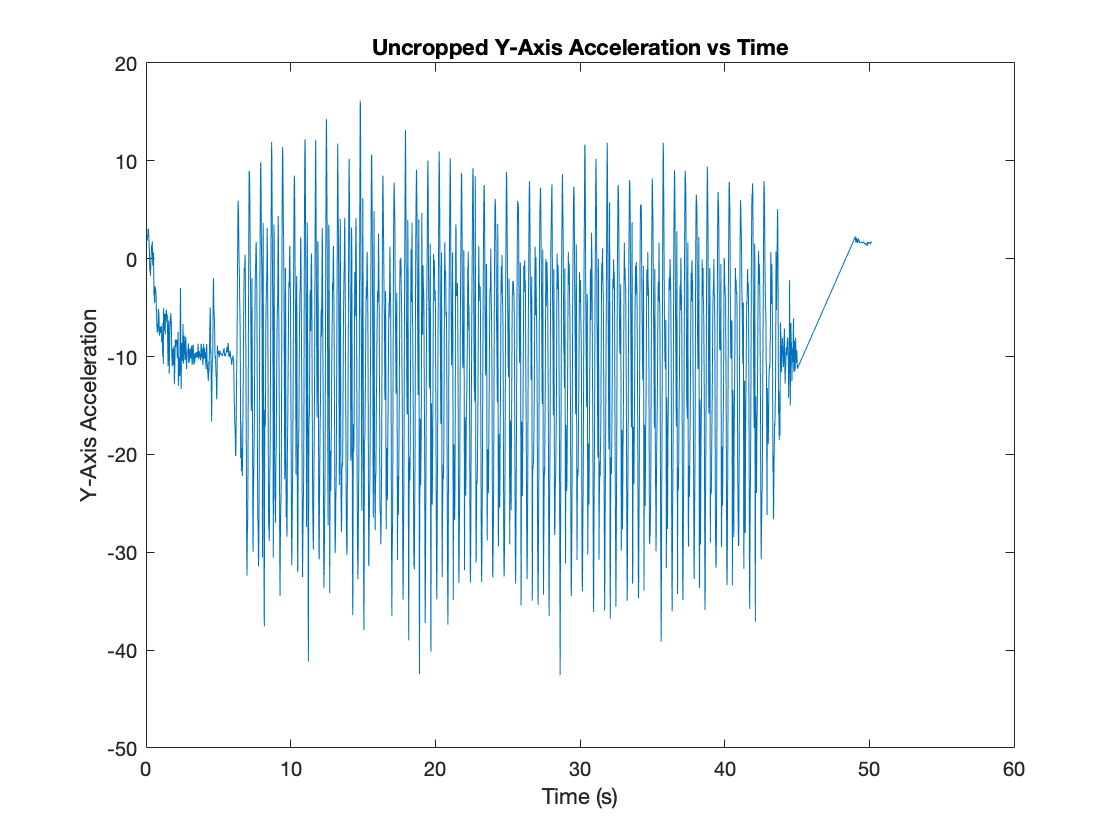


% FINALtoestrike_yaxis;
plot(FINALtoestrike_finalArray(:,1), FINALtoestrike_finalArray(:,3));
title("Uncropped Y-Axis Acceleration vs Time");
xlabel("Time (s)");
ylabel("Y-Axis Acceleration");

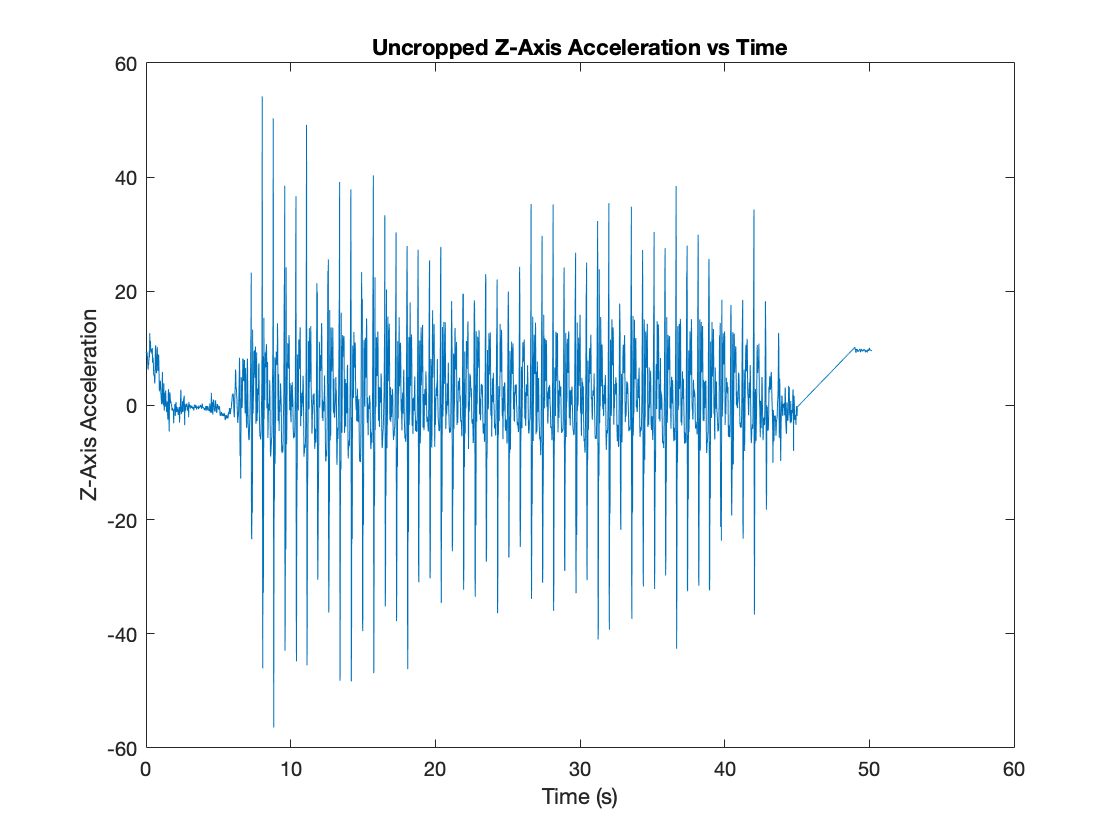


% FINALtoestrike_zaxis;
plot(FINALtoestrike_finalArray(:,1), FINALtoestrike_finalArray(:,4));
title("Uncropped Z-Axis Acceleration vs Time");
xlabel("Time (s)");
ylabel("Z-Axis Acceleration");





% UNIMPORTANT - USED TO FIGURE OUT INDEX -->  plot(midfoot_finalArray(751:1376, 1), midfoot_finalArray(751:1376, 4)); % z acceleration vs time (CROPPED) NEED TO CHANGE THE SCALE (?)
% Crop data at t = 10.0120 - 40.00
% V = valid data that we can use
VFINALtoestrike_time_data = FINALtoestrike_finalArray(619:2470, 1);
VFINALtoestrike_xaxis_data = FINALtoestrike_finalArray(619:2470, 2);
VFINALtoestrike_yaxis_data = FINALtoestrike_finalArray(619:2470, 3);
VFINALtoestrike_zaxis_data = FINALtoestrike_finalArray(619:2470, 4);

% new array for midfootStep data
FINALtoestrike_FINAL = [VFINALtoestrike_time_data VFINALtoestrike_xaxis_data VFINALtoestrike_yaxis_data VFINALtoestrike_zaxis_data] % <==== THIS IS THE DATA ARRAY THAT WE ARE USING

FINALtoestrike_FINAL =    10.0120    0.4211  -13.5943   -2.1691
   10.0280    2.4471  -16.6147   -2.9432
   10.0440    3.4078  -23.0004    1.2578
   10.0610    2.8665  -28.5250    3.5699
   10.0770    1.1301  -31.3307    2.2735
   10.0930    0.1639  -29.2676   -0.2314
   10.1090   -3.6704  -25.8105    4.1016
   10.1250   -8.2381  -23.2697    2.2170
   10.1420  -11.8113  -20.8665    1.4671
   10.1580   -7.5433  -16.3147    0.1284


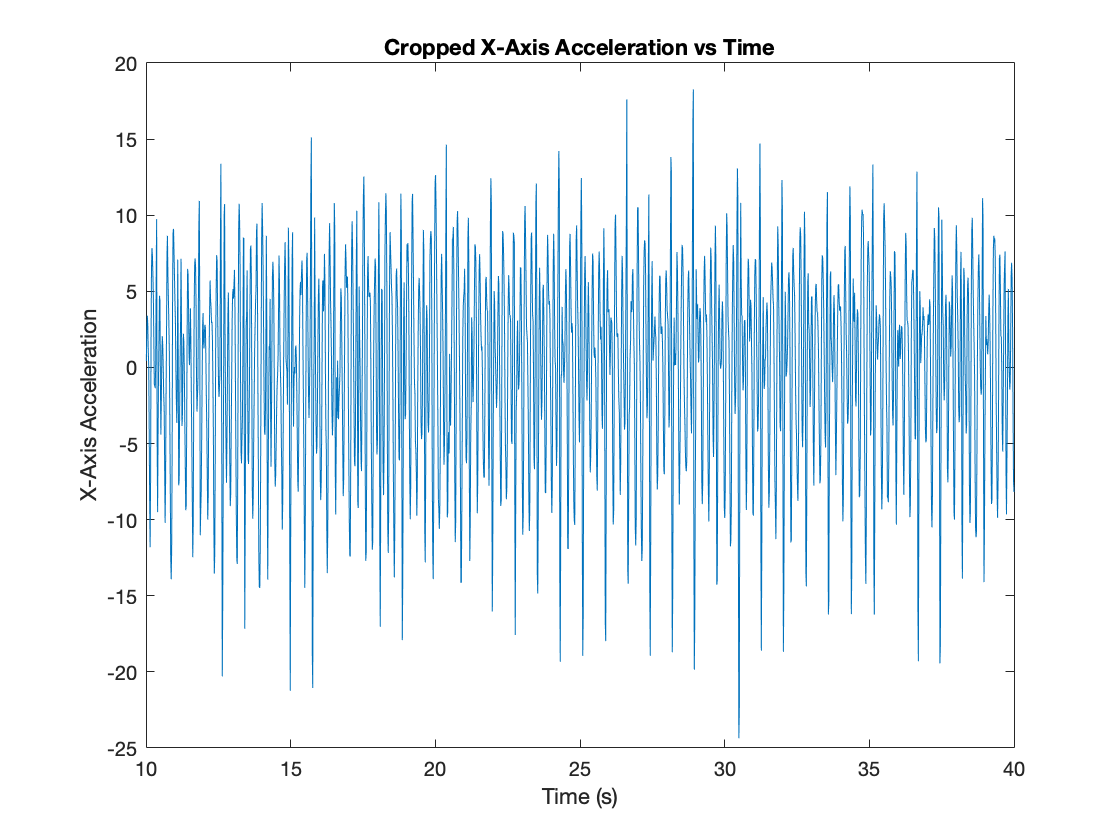


% %---- New Cropped WALTER Data - PLOTS -----
        
%Cropped data for x-axis acceleration vs time
plot(FINALtoestrike_FINAL(:,1), FINALtoestrike_FINAL(:,2));
title("Cropped X-Axis Acceleration vs Time");
xlabel("Time (s)");
ylabel("X-Axis Acceleration");

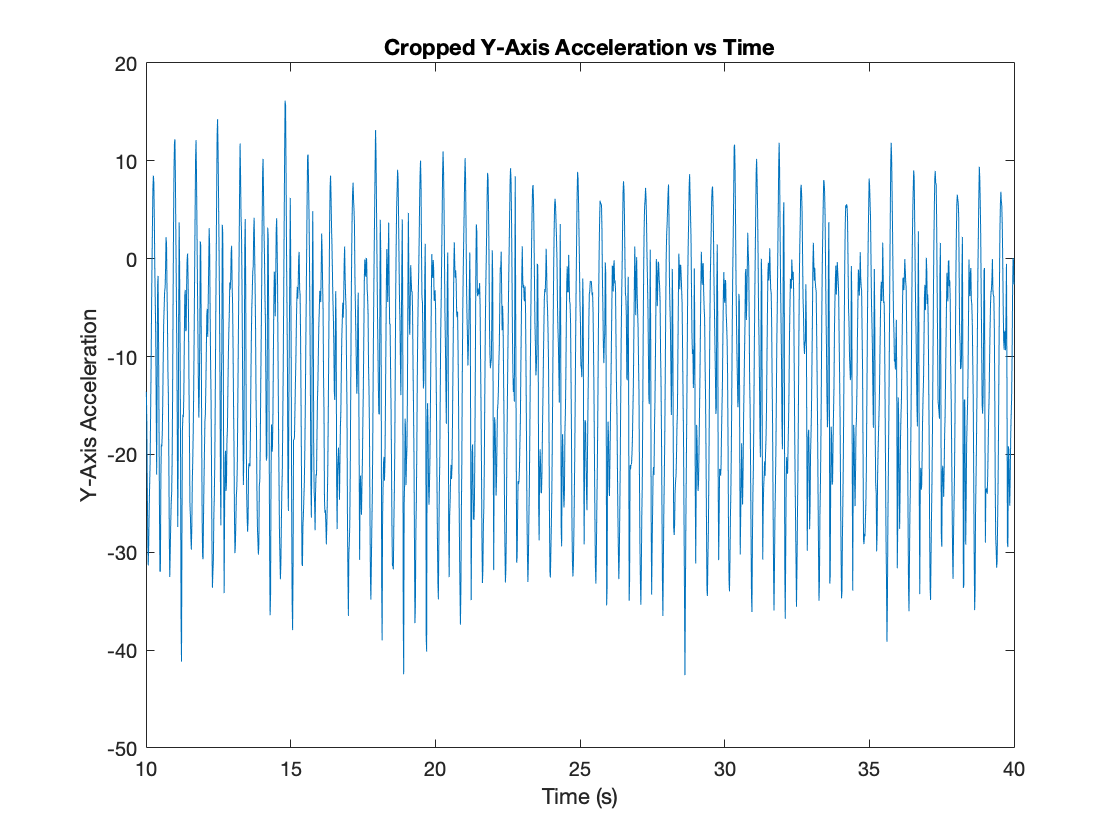



%Cropped data for y-axis acceleration vs time
plot(FINALtoestrike_FINAL(:,1), FINALtoestrike_FINAL(:,3));
title("Cropped Y-Axis Acceleration vs Time");
xlabel("Time (s)");
ylabel("Y-Axis Acceleration");

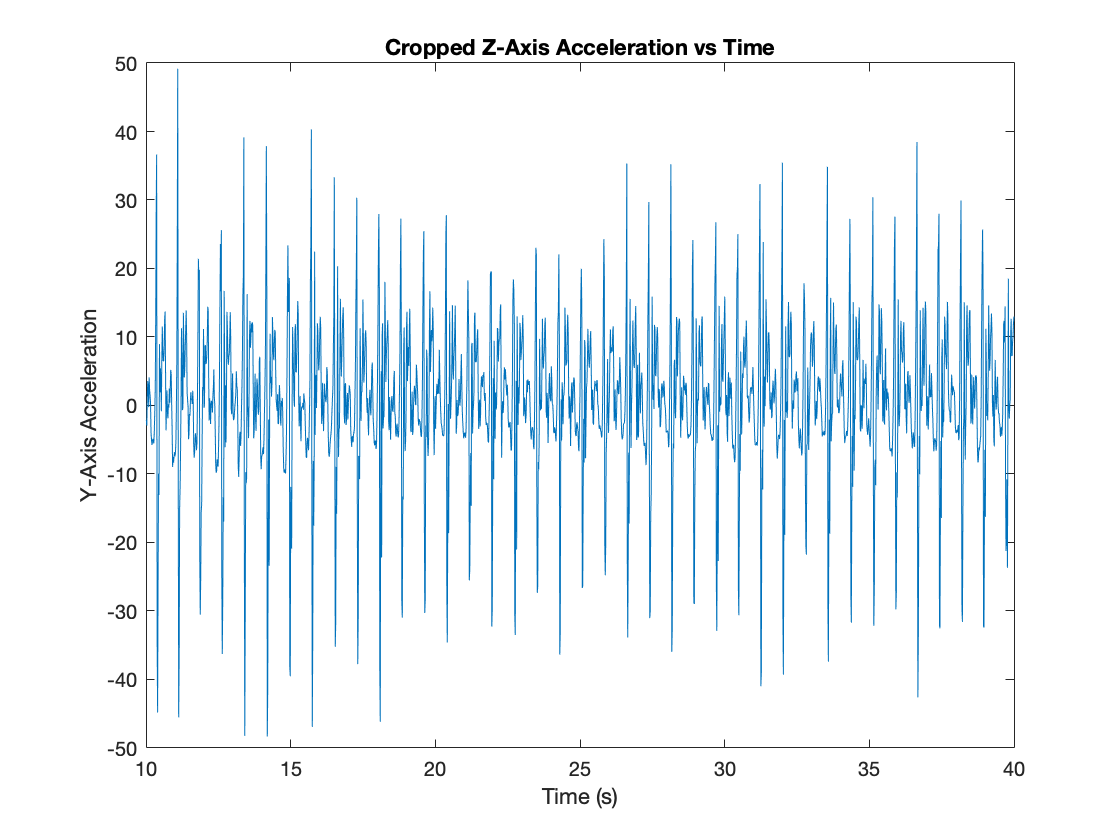


%Cropped data for z-axis acceleration vs time
plot(FINALtoestrike_FINAL(:,1), FINALtoestrike_FINAL(:,4));
title("Cropped Z-Axis Acceleration vs Time");
xlabel("Time (s)");
ylabel("Y-Axis Acceleration");

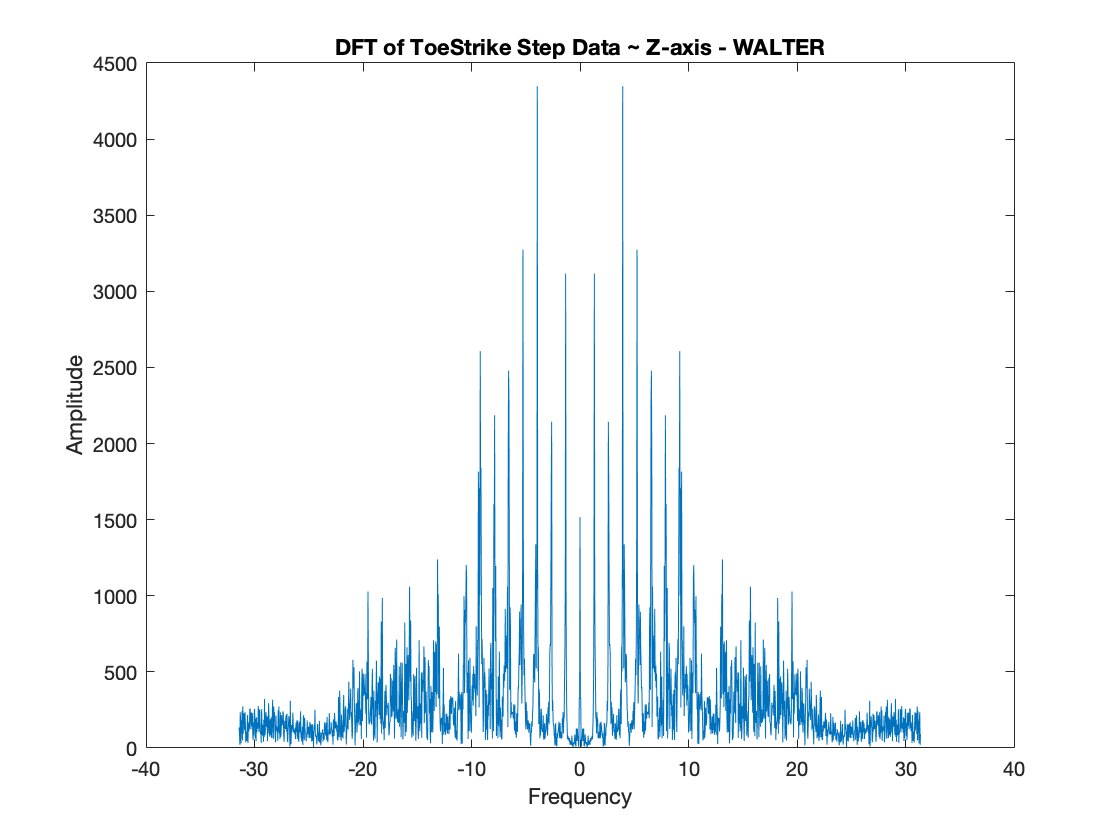



% Plotting the DFT for Z-Axis Acceleration %
P_FINALtoestrike = fftshift(fft(FINALtoestrike_FINAL(:,4)));
Fs = 10; %sampling frequency (Hz)
N_FINALtoestrike = length(P_FINALtoestrike);
F_FINALtoestrike = (linspace(-pi, pi-2/N_FINALtoestrike*pi, N_FINALtoestrike) + pi/N_FINALtoestrike*mod(N_FINALtoestrike,2))* Fs; %Domain in Hertz%


plot(F_FINALtoestrike,abs(P_FINALtoestrike')) % Plotting the DFT
title("DFT of ToeStrike Step Data ~ Z-axis - WALTER");
xlabel("Frequency");
ylabel("Amplitude");